# **Planning and Navigation**

Navigation is the ability of a robot to reach a goal using its map and sensor data. It combines two parts:

- **Planning** → decide a path 

- **Reacting** → handle changes during motion 

Both are required. A plan alone fails in dynamic scenes. Reactive control alone cannot guide long-range motion. 

## Planning and Reacting

Within artificial intelligence, planning and reacting are sometimes viewed as opposing paradigms. However, when applied to physical systems such as mobile robots, the two are highly complementary, each is essential for successful navigation. A robot must:

- **Plan** a course of action to reach a goal, and

- **React** to unforeseen events during execution to ensure the plan remains achievable.

Without reactive behavior, even a perfect plan may fail due to unmodelled obstacles or dynamic environmental changes. Without planning, reactive behavior alone cannot guide the robot toward distant goals. Thus, effective navigation requires both.  An information-theoretic formulation makes this complementarity clearer. Suppose robot $R$ at time $t$ has a map $M$ and an initial belief state $b_t$. The robot’s objective is to reach a physical location $p$ while satisfying temporal constraints $\text{loc}_t(R) = p \; ; \; (t \leq n)
$. However, because the robot senses its *belief state* rather than its true physical position, reaching location $p$ is equivalent to achieving a belief state $b_g$ corresponding to certainty that $\text{loc}(R) = p$. A plan $\pi$ is therefore a sequence of actions (or a trajectory) that transforms the robot’s belief state from $b_t$ to $b_g$, assuming the world is consistent with both $b_t$ and $M$. In reality, these assumptions often do not hold:

- the robot’s position may not match the initial belief,

- the map may be incomplete or partially incorrect, and

- the environment may be dynamic, invalidating the planner’s model.

To overcome this mismatch, the robot must incorporate new sensory information during execution. Reactive control adjusts the robot’s motion locally to stay safe and maintain progress toward the goal. In some cases, new information may invalidate the original plan, requiring the planner to revise or replan accordingly.

# **Navigation Problem Formulation**

Before choosing any algorithm, we must define **what the robot is trying to solve**.

In navigation, the problem is not just “find a path.” It is:

**Given a robot, a map (possibly incomplete), and a goal, compute a sequence of actions that safely moves the robot to the goal while respecting constraints.**

A navigation problem can be defined using four elements:

**1. State (Configuration)**

- Robot pose: $q = (x, y, \theta)$

- Or for a circular robot: $q = (x, y)$

This is the robot’s position in **configuration space**.

**2. Map (Environment Model)**

- Known map → static obstacles 

- Partial map → uncertainty 

- No map → rely on sensors 

In practice:

- Global planner → uses map 

- Local planner → uses sensors 

**3. Goal**

- Target position or pose Can be: 

- Exact (x, y, θ) 

- Region 

- Sequence of waypoints 

**4. Action / Control**

- Robot moves using control inputs: 

- Linear velocity v

- Angular velocity ω

The output of planning is:

$\text{Plan} = \{u_1, u_2, ..., u_n\}$or a **trajectory/path**

## Configuration Space (C-space)

In robotics navigation and planning, the **Configuration Space** (often abbreviated as **C-space**) is a fundamental mathematical framework used to represent all possible positions and orientations of a robot.

Instead of treating a robot as a complex geometric shape moving through a world of physical obstacles (Workspaces), C-space simplifies the problem by representing the entire robot as a **single point** in a multi-dimensional space.

A **configuration** $$q$$ is a complete specification of every point on the robot. The set of all possible configurations is the Configuration Space, denoted as $$C$$.

- **Degrees of Freedom (DoF):** The dimension of the C-space is equal to the number of degrees of freedom of the robot.

- $$C_{free}$$**:** The set of configurations where the robot does not collide with any obstacles or itself.

- $$C_{obs}$$**:** The set of configurations that result in a collision.

The goal of navigation is to find a continuous path in $$C_{free}$$ from a starting configuration $$q_{start}$$ to a goal configuration $$q_{goal}$$.

**Workspace vs. Configuration Space**

The **Workspace (**$$W$$**)** is the 2D or 3D physical environment where the robot exists.

- In $$W$$, a robot has a specific geometry (e.g., a rectangle or an arm).

- In $$C$$, the robot is a **point**, but the obstacles are "grown" or transformed to account for the robot's shape and size.

**The Transformation Process (Minkowski Sum)**

To convert a workspace obstacle into a C-space obstacle for a translating robot, we mathematically "slide" the robot around the obstacle. The resulting shape in C-space represents all the points where the robot's reference point would cause a collision.

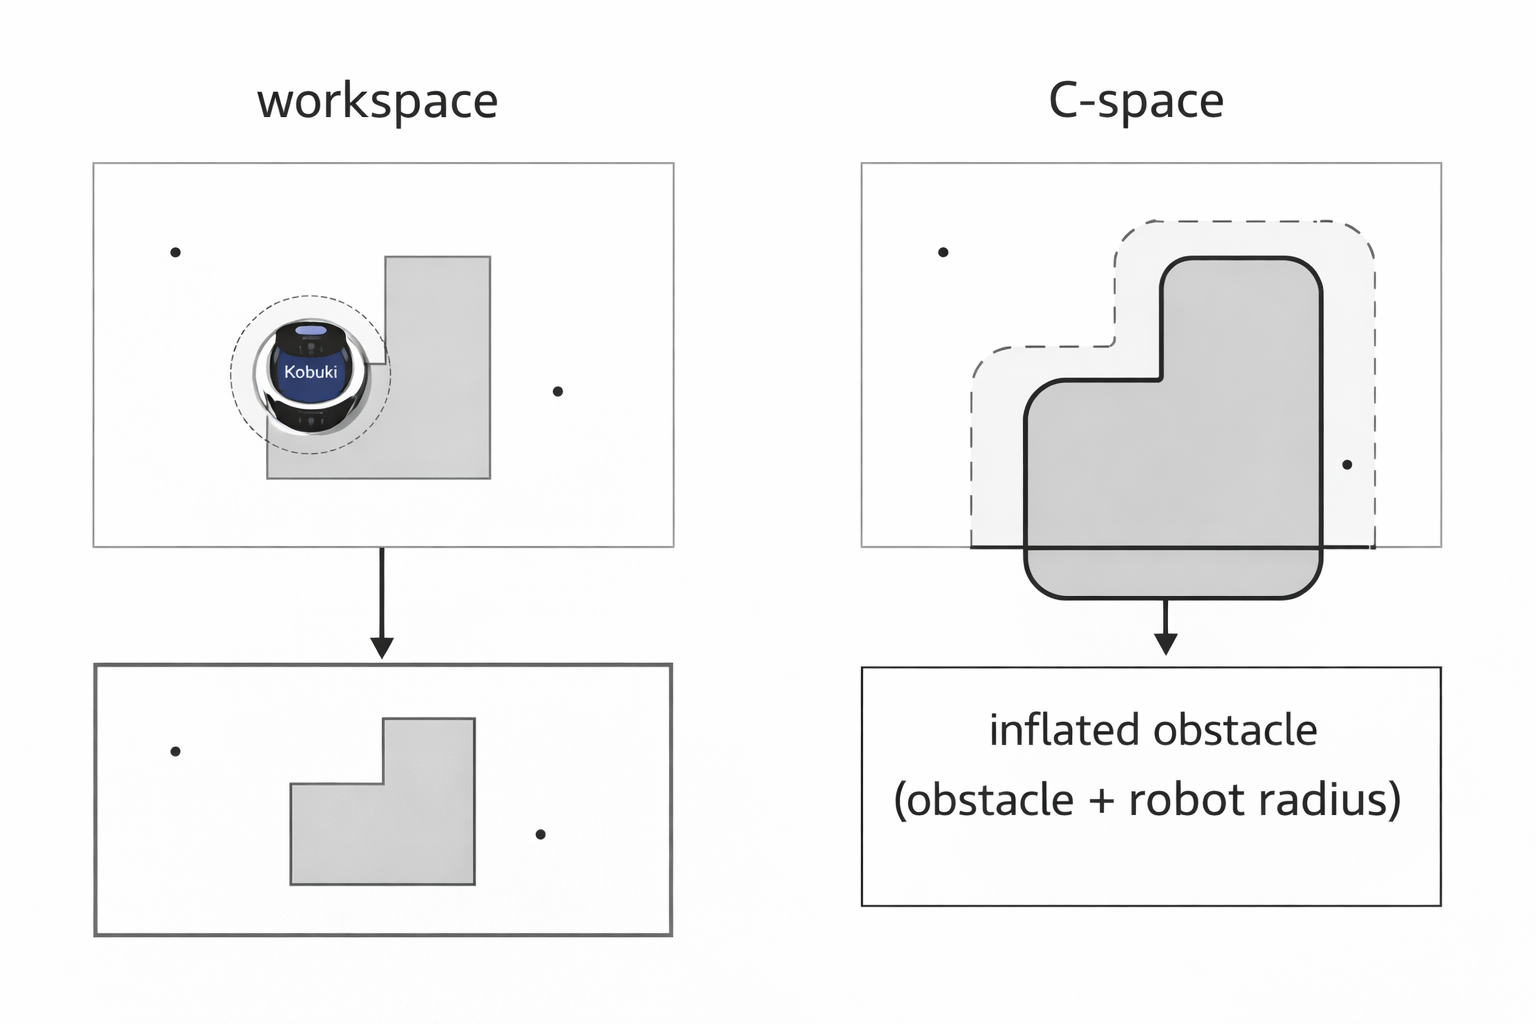

## Constraints

Constraints define what motions are allowed:

**1. Kinematic Constraints**

Kinematic constraints describe the allowable motions based on the mechanical structure and geometry of the robot, independent of the forces causing that motion.

**2. Dynamic Constraints**

Dynamic constraints involve the physics of motion—mass, inertia, and the forces/torques required to move. Even if a path is kinematically possible, it may be dynamically infeasible.

- **Velocity and Acceleration Limits:** Actuators (motors) have maximum RPMs and torque outputs. A robot cannot instantaneously reach its top speed, nor can it stop instantly.

- **Momentum and Inertia:** For heavy robots or high-speed underwater vehicles (like the fish-inspired robots you've researched), the "drift" caused by momentum must be accounted for.

- **Stability:** For bipedal or high-center-of-gravity robots, certain accelerations might cause the robot to tip over. The planner must ensure the **Zero Moment Point (ZMP)** remains within the support polygon.

**3. Environmental Constraints**

These are external factors imposed by the surroundings. They define the boundaries  (Free Space).

- **Static Obstacles:** Fixed structures like walls or furniture. These define the "holes" in your configuration space.

- **Dynamic Obstacles:** Moving entities like humans, other robots, or debris. In dynamic environments, the C-space itself is time-varying, requiring high-speed **replanning** or predictive models like Velocity Obstacles (VO).

- **Narrow Passages:** These are regions  that are barely wider than the robot. They represent a significant challenge for sampling-based planners (like RRT) because the probability of "randomly" hitting a configuration inside a narrow gap is very low, often requiring specialized sampling heuristics.

# **Algorithm Characteristics**

## Completeness

A central concept in evaluating robot navigation architectures is completeness. A robot system is *complete* if, for every possible problem (given initial belief, map, and goal), the system is guaranteed to find a solution whenever one exists. Conversely, an *incomplete* system fails on at least one solvable problem.

## Optimality

The concept of **Optimality** serves as a rigorous performance metric for evaluating the efficiency of a navigation architecture. A robot system is defined as optimal if, for every solvable problem, the system is guaranteed to find the best possible solution according to a specific cost criterion. In this framework, "best" is quantified by a cost functional $$J(\sigma)$$, which assigns a real-valued scalar to any valid path $$\sigma$$ based on parameters like Euclidean distance, time, or energy expenditure. Mathematically, a system is optimal if it returns a path $$\sigma^*$$ such that $$J(\sigma^*) \leq J(\sigma)$$ for all other feasible paths $$\sigma$$ connecting the same start and goal configurations.

Conversely, a system is **Suboptimal** if it returns a solution that satisfies the goal and collision-avoidance constraints but does so at a higher cost than the theoretical minimum. While an optimal system finds the absolute shortest or most efficient route, a suboptimal system may prioritize speed of computation or simplicity, providing a "good enough" path that is found much faster than the true optimum. This trade-off is often necessary in real-time environments where the time spent searching for the absolute minimum cost might outweigh the benefits of the efficiency gained during execution.

A distinct category frequently used in modern research is **Asymptotic Optimality**. A system possesses this characteristic if the cost of the path it produces is guaranteed to converge toward the true optimum $$J(\sigma^*)$$ as the computational resources or the number of iterations given to the algorithm approach infinity. This allows a planner to provide a quick initial solution that is safe but potentially inefficient, and then continuously refine that path into a more optimal trajectory as long as the robot remains in a planning state. This property is especially valuable in high-dimensional spaces where finding the absolute optimum immediately is computationally prohibitive.

## Computational Complexity

**Computational Complexity** serves as the primary metric for evaluating the scalability and efficiency of a navigation **algorithm** as the environment grows in size or the robot increases in complexity. An **algorithm** is characterized by its complexity based on the resources (specifically **Time** and **Memory) **required to compute a valid motion plan. In this context, time complexity refers to the number of operations the **algorithm** must perform to reach a decision, while space complexity refers to the amount of memory consumed to store the map, the search tree, or the state configurations during the planning process.

An **algorithm** exhibits **High Complexity** if the computational resources required grow exponentially as the number of dimensions in the configuration space increases. This phenomenon, often called the "curse of dimensionality," means that while an **algorithm** might find a path in a simple 2D room in milliseconds, the same **algorithm** might take hours to solve a problem involving a 7-degree-of-freedom robotic arm or a soft underwater robot. Conversely, an **algorithm** with **Low Complexity** or **Polynomial Complexity** is one that scales efficiently, allowing it to maintain real-time performance even as the complexity of the robot's joints or the density of the environment obstacles increases.

## Path Planning for Mobile Robots

For mobile robots operating on flat ground, the robot’s configuration is commonly represented using three variables $(x,\, y,\, \theta)$. However, most wheeled mobile robots are nonholonomic like differential-drive and Ackermann-steered systems. Their nonholonomic constraints restrict the allowable velocities: $(\dot{x}, \dot{y}, \dot{\theta})$ at each configuration $(x,y,\theta ).$ In practice, mobile roboticists commonly simplify the problem by treating the robot as if it were holonomic during planning. This is especially reasonable for differential-drive robots, which can rotate in place and therefore approximate holonomic behavior whenever the orientation is not critical. A second common simplification is to approximate the robot as a point. In this reduced representation, the configuration space collapses from three dimensions to just the 2D plane-$(x, y)
$ corresponding to the robot’s position. 

# Artificial Potential Field

Artificial Potential field path planning constructs a scalar field (an artificial potential) over the robot’s map that guides the robot toward the goal while pushing it away from obstacles. In this method, the robot is treated as a point subject to an artificial potential function $U\left(q\right)\ldotp$ The robot moves by following the negative gradient of this potential, much like a ball rolling downhill. The goal forms a minimum (attractive basin), while obstacles form peaks (repulsive regions). The sum of these influences produces a smooth field that directs the robot toward the goal while avoiding known obstacles.

The robot is attracted to the goal and repelled from obstacles. If new obstacles appear, their effect can be incorporated by updating the potential field. For simplicity, we treat the robot as a point and ignore orientation, making the potential field a function of planar position $q=(x,y)$. If the potential function $U\left(q\right)$ is differentiable, the artificial force acting on the robot is given by $F(q) = - \nabla U(q),
$ where $\nabla U(q)$ is the gradient of the potential at configuration $q$. The potential is typically decomposed into attractive and repulsive components  $U(q) = U_{\text{att}}(q) + U_{\text{rep}}(q),$ and correspondingly, $F(q) = F_{\text{att}}(q) + F_{\text{rep}}(q). $ A common form of attractive potential is the parabolic model $U_{\text{att}}(q) = \frac{1}{2} k_{\text{att}} \, p_{\text{goal}}(q)^2$, where $k
_att
	

>0 \text{ is a scaling constant,}$ $p_{\text{goal}}$ is the Euclidean distance to the goal. The corresponding attractive force $F_{\text{att}}(q) = - \nabla U_{\text{att}}(q) = -k_{\text{att}} \, p_{\text{goal}}(q)\, \nabla p_{\text{goal}}(q)
$. This force smoothly decreases to zero as the robot approaches the goal. The repulsive potential prevents the robot from approaching obstacles too closely. It is designed to be strong near obstacles but negligible far away. A common formulation is given by $U_{\text{rep}}(q) = \begin{cases} \displaystyle \frac{1}{2} k_{\text{rep}} \left( \frac{1}{p(q)} - \frac{1}{p_0} \right)^2, & \text{if } p(q) \le p_0, \\[10pt] 0, & \text{if } p(q) > p_0, \end{cases}$ where $ k_{rep}>0$ is a scaling factor, $p\left(q\right)$ is the minimum distance from $q$ to any obstacle, and $p_0$ defines the obstacle’s influence radius. The repulsive force becomes  $F_{\text{rep}}(q) = \begin{cases} k_{\text{rep}} \left(\frac{1}{p(q)} - \frac{1}{p_0}\right) \frac{1}{p(q)^2} \nabla p(q), & \text{if } p(q) \le p_0,\\[10pt] 0, & \text{if } p(q) > p_0, \end{cases}$  pushing the robot away from obstacles. The total force is given by $F(q) = F_{\text{att}}(q) + F_{\text{rep}}(q)
$.

While intuitive and computationally efficient, potential fields have two major drawbacks:

- **Local minima: **The combined potential may contain points other than the goal where the gradient becomes zero. The robot can get stuck at these locations.

- **Concave obstacles: **For nonconvex shapes, multiple nearest-obstacle points may exist, leading to oscillations or unstable behavior.

These issues compromise **completeness** and are a well-known weakness of basic potential field methods.

## Try Yourself: Potential Field Navigation 

This example shows how a robot plans motion using a **potential field method**.

Instead of searching for a path explicitly, the robot moves under the influence of **virtual forces**:

- attraction toward the goal 

- repulsion away from obstacles 

** What the Code Does**

At each step, the robot computes forces and updates its position.

** 1. Attractive Force (Goal Seeking)**

The robot is pulled toward the goal:

`F_att = k_att * (goal - pos)`

- Points directly to the goal 

- Strength depends on distance 

 This ensures the robot keeps moving toward the target.

**2. Repulsive Force (Obstacle Avoidance)**

Each obstacle pushes the robot away:

`F_rep ∝ (pos - obs)`

- Only active within a distance `d0`

- Stronger when the robot is closer to the obstacle 

This prevents collisions.

** 3. Total Force**

`F = F_att + F_rep`

- Combines goal attraction and obstacle avoidance 

- The robot moves in the direction of this force 

**4. Motion Update**

`pos = pos + step_size * normalized(F)`

- Direction comes from force 

- Step size controls speed 

** 5. Potential Field (Right Plot)**

The contour plot shows the **energy landscape**:

- Goal → low potential (valley) 

- Obstacles → high potential (peaks) 

The robot moves “downhill” in this landscape.

** What to Observe****Left Plot (Motion)**

- Shows actual robot movement 

- Path curves around obstacles 

**Right Plot (Contours)**

- Shows why the robot moves that way 

- Dense contours → strong forces 

**Force Vector**

- Arrow shows direction of motion 

- Always points toward lower potential 

**What You Can Tune**

1. Obstacles (`obs`**)**

- Change number and position 

- Create narrow passages or walls 

**2. Attraction (**`k_att`**)**

- High → aggressive motion toward goal 

- Low → slower movement 

**3. Repulsion (**`k_rep`**)**

- High → strong avoidance (may oscillate) 

- Low → weak avoidance (risk of collision) 

**4. Influence Distance (**`d0`**)**

- Large → early avoidance 

- Small → late avoidance 

**5. Step Size (**`step_size`**)**

- Large → fast but unstable 

- Small → smooth but slow 

**Important Design Detail**

Repulsion is reduced near the goal:

`scale = min(1, goal_dist/5)`

 Without this:

- robot may never reach the goal 

- gets pushed away near the target 

%% 🌊 Task: Potential Field 

pos = [2 2];        
% 👉 Initial robot position
% Try changing start location (e.g., [5 5], [1 18])

goal = [18 18];     
% 👉 Goal position
% Move goal to see different paths

% ===== 🔧 MULTIPLE OBSTACLES (EDIT THIS) =====
obs = [10 10;
       12 14;
       6  12];   
% 👉 Add/remove obstacles or create walls
% Example:
% obs = [8 10; 9 10; 10 10; 11 10; 12 10];  % vertical wall

% ===== 🔧 PARAMETERS TO TUNE =====
k_att = 0.05;    
% 👉 Attraction strength toward goal
% High → faster, aggressive motion
% Low → slow movement

k_rep = 8;       
% 👉 Repulsion strength from obstacles
% High → strong avoidance (may oscillate)
% Low → may collide with obstacles

d0 = 5;          
% 👉 Influence distance of obstacles
% Large → obstacles affect robot earlier
% Small → robot reacts late

step_size = 0.3;
% 👉 How far robot moves per step
% Large → faster but unstable
% Small → smooth but slow

% =====================================================

[X,Y] = meshgrid(1:20,1:20);

figure

for t = 1:150
    
    clf   % clear figure each frame
    
    %% ===== FORCE COMPUTATION =====
    
    % --- Attractive force (toward goal) ---
    F_att = k_att*(goal - pos);
    
    % --- Repulsive force (from all obstacles) ---
    F_rep = [0 0];
    
    for i = 1:size(obs,1)
        d = norm(pos - obs(i,:));
        
        if d < d0   % only nearby obstacles affect robot
            
            % 👉 Reduce repulsion near goal (important!)
            goal_dist = norm(pos - goal);
            scale = min(1, goal_dist/5);
            
            F_rep = F_rep + scale * ...
                k_rep*(pos - obs(i,:))*(1/d - 1/d0)/(d^3 + 0.1);
        end
    end
    
    % --- Total force ---
    F = F_att + F_rep;
    
    % --- Motion update (normalized for stability) ---
    pos = pos + step_size * F / (norm(F)+1e-6);
    
    %% ===== STOP CONDITION =====
    if norm(pos - goal) < 0.5
        break
    end
    
    %% ===== SUBPLOT 1: ROBOT MOTION =====
    subplot(1,2,1)
    
    plot(goal(1),goal(2),'gx','LineWidth',2); hold on
    plot(obs(:,1),obs(:,2),'ro','MarkerFaceColor','r')
    plot(pos(1),pos(2),'bo','MarkerFaceColor','b')
    
    xlim([0 20]); ylim([0 20])
    title('Robot Motion')
    grid on
    
    %% ===== SUBPLOT 2: POTENTIAL FIELD =====
    subplot(1,2,2)
    
    % --- Compute potential field ---
    U = k_att*((X-goal(1)).^2 + (Y-goal(2)).^2);
    
    for i = 1:size(obs,1)
        d = sqrt((X-obs(i,1)).^2 + (Y-obs(i,2)).^2);
        mask = d < d0;
        
        U(mask) = U(mask) + k_rep*(1./d(mask) - 1/d0).^2;
    end
    
    contour(X,Y,U,20); hold on
    
    % --- Draw elements ---
    plot(goal(1),goal(2),'gx','LineWidth',2)
    plot(obs(:,1),obs(:,2),'ro','MarkerFaceColor','r')
    plot(pos(1),pos(2),'bo','MarkerFaceColor','b')
    
    % --- Show force direction ---
    quiver(pos(1),pos(2),F(1),F(2),0,'k','LineWidth',2)
    
    xlim([0 20]); ylim([0 20])
    title('Potential Field (Contours + Force)')
    grid on
    
    pause(0.05)
end

# Graph Search

Graph-search techniques have deep mathematical roots, but much recent innovation has come from the robotics community, largely driven by the need for real-time algorithms that can accommodate evolving maps. Most graph-based planning methods split naturally into two stages:

- **Graph construction** — place nodes and connect them with edges so the graph captures the free space while keeping size manageable.

- **Graph search** — run a search algorithm on that graph to compute a (usually optimal or near-optimal) path.

**Graph construction**

Given a representation of free and occupied space, the challenge is to produce a graph that lets the robot reach any reachable part of the free space while keeping graph complexity reasonable. Typical approaches include:

**Roadmaps**

- **Visibility graph: **The **visibility graph** for a polygonal configuration space $C$ is formed by connecting every pair of vertices that are mutually visible (this set includes the start and goal as additional vertices). Each edge is the unobstructed straight-line segment between two visible vertices,therefore every road in the visibility graph is a shortest possible straight-line connection between its endpoints. Path planning then reduces to finding a shortest path from start to goal that follows these roads. Visibility graphs are popular in mobile robotics because they are conceptually simple and directly exploit polygonal obstacle descriptions (whether the environment is represented continuously or on a discretized map). However, two important caveats affect their practical use:  (1) **Scalability:** The number of nodes and edges grows with the number of obstacle vertices. Visibility graphs work very efficiently in sparse environments, but in cluttered scenes the representation can become large and the graph-search slow. (2) **Clearance/safety:** Shortest paths on a visibility graph are length-optimal, which tends to pull planned paths extremely close to obstacle boundaries. This optimality trades away any built-in margin of safety. Practitioners usually address this by either inflating obstacles by more than the robot’s radius prior to building the graph, or  post-processing the resulting path to increase clearance. Both remedies reduce or eliminate the theoretical length-optimality of the raw visibility-graph solution, but they substantially improve practical safety and robustness.

- **Voronoi diagram:** In contrast to the visibility graph, a Voronoi diagram provides a complete roadmap that tends to maximize the robot’s distance from obstacles. For every point in free space, we compute its distance to the nearest obstacle. If this distance is visualized as a height value, the plot rises as we move away from obstacles. The **ridges** of this distance function, i.e., the points equidistant to two or more obstacles form the Voronoi diagram. For polygonal obstacles, the Voronoi diagram consists of a set of straight-line segments and parabolic arcs.  A key feature of the Voronoi diagram is **completeness, i**f a path exists in the free space, then a corresponding path exists along the Voronoi edges. Thus, like the visibility graph, Voronoi-based planning is complete. However, these paths are not length-optimal, they frequently take long detours to maintain maximum clearance. 

**Cell decomposition**

- **Exact cell decomposition:** Partition free space into cells that are entirely free or occupied (cell boundaries follow geometric critical features). Resulting graph is lossless and complete, but the number of cells depends strongly on environment complexity, efficient for large sparse maps but costly for cluttered scenes. Exact decomposition is less commonly used in practice because of implementation complexity.

- **Approximate cell decomposition:** Implemented as fixed-size grids (occupancy grids) or adaptive quad/octrees. Fixed grids are simple but can miss narrow passages if the cell size is too coarse; in practice cells are chosen small (e.g., a few cm) to avoid that. Adaptive decompositions recursively split space and can support hierarchical planning, coarse-to-fine search reduces computation while preserving finer detail when needed.

**Lattice graphs**

- Lattices are formed by repeating a base pattern of feasible edges across the workspace. Unlike generic grids, lattice edges are designed to be **kinematically executable** for a given robot (e.g., include curvature or heading as part of state). Lattices are typically precomputed for a platform, so found paths map directly to feed-forward controls. They represent an approximate decomposition and are especially valuable when executability and control fidelity matter.

# Deterministic graph search

Once the environment has been converted into a connectivity graph using any of the graph-generation methods, the task of path planning becomes finding the *best* path between the start and goal nodes. “Best” typically refers to the selected optimization criterion such as minimum total cost or shortest path length. Because many graph-search methods share structural similarities, it is useful to define the core cost components that distinguish them. For a node $n$ (and an adjacent node $n\prime$), we define:

- **Path cost**: Denoted by $g\left(n\right)$ is the accumulated cost from the start node to $n$

- **Edge traversal cost**: Denoted by $c\left(n,n\prime \right)$ is the incremental cost of moving from nnn to its neighbor $n\prime$

- **Heuristic cost**:Denoted by $h\left(n\right)$ is an estimate of the remaining cost from nnn to the goal

- **Expected total cost**: Given by $f(n) = g(n) + \varepsilon \, h(n)$ where $\varepsilon$ is a parameter that varies across algorithms.

**Case 1: Uniform edge costs: **When all edges have the same traversal cost, simple implementations of breadth-first search (BFS) or depth-first search (DFS) can be used. These methods are computationally efficient, but they do not handle variable edge costs.

In these cases, $\varepsilon =0$ and heuristics are not needed. 

**Case 2: Nonuniform edge costs: **When edges have different traversal costs, algorithms such as Dijkstra’s algorithm are required. These algorithms guarantee optimality but typically incur higher computational complexity. Again, they correspond to the case $\varepsilon =0$.

**Case 3: Heuristic-guided search: **For $\varepsilon \not= 0$, a heuristic function $h\left(n\right)$ is used to guide the search more directly toward the goal. To preserve optimality, the heuristic must be consistent and admissible (i.e., must underestimate the true cost-to-goal). Most useful heuristics in robotics satisfy these conditions.

- Setting $\varepsilon =1$ yields the optimal A* algorithm.

- Setting $\varepsilon > 1$  produces suboptimal or greedy A* variants, which may sacrifice optimality for speed.

With these distinctions established, we now examine the major deterministic search algorithms used in mobile robotics.

**Breadth-first search (BFS):** BFS begins by expanding the start node and then exploring all of its immediate neighbors. For each of those neighbors, BFS expands their unexplored neighbors, and so on. This iterative process marking a node *active*, generating its neighbors as *open*, and then marking the node *visited*—is called node expansion. BFS expands nodes strictly in order of their proximity to the start, where proximity is measured by the minimum number of edge transitions. The algorithm terminates as soon as the goal node is reached. Because nodes are naturally explored in increasing distance from the start, BFS does not require any reordering of the open list, which makes it computationally simple. A key property of BFS is that it always returns the path with the fewest number of edges between the start and the goal. If all edge traversal costs are identical then BFS also finds the optimal-cost path. Re-expansion of previously visited nodes can be prevented by assigning each node a “visited” flag, without affecting optimality.

**Depth-first search: **Unlike breadth-first search (which explores all nodes at a given depth before moving deeper) DFS proceeds by expanding each node as far down a branch as possible. It continues along that branch until it either reaches a node with no successors or encounters a dead end. At that point, DFS backtracks to the most recent branching point and explores the next unexplored successor. This process continues until the goal is found or all reachable nodes have been explored.

A major inconvenience of naive DFS is that it may revisit previously visited nodes or follow redundant paths. In practical implementations, however, this can be avoided by maintaining a visited-node record, preventing unnecessary revisits. Despite not guaranteeing optimal paths, DFS offers a strong advantage in terms of space efficiency. Unlike breadth-first search which must store all nodes at the current frontier, DFS needs to store only:

- the current path from the start to the active node, and

- the unexpanded siblings of each node on that path.

Once a node has been fully expanded and all of its descendants explored, it can be safely discarded from memory. This makes DFS particularly well suited for environments where memory is limited, or where the depth of the solution is expected to be large relative to branching factor.

**Dijkstra’s algorithm: **Dijkstra’s algorithm, named after E. W. Dijkstra, extends the principles of breadth-first search to graphs in which edges can have arbitrary positive costs. Despite this added flexibility, the algorithm still guarantees optimal solutions. Handling nonuniform edge costs introduces additional computational overhead, requiring the use of a heap (priority queue), a specialized tree-based data structure. In the heap data structure, nodes waiting for expansion are ordered by a key corresponding to their expected total path cost, $f\left(n\right)$. Since Dijkstra’s algorithm does not use a heuristic, this simplifies to $f\left(n\right)=g\left(n\right),$ the cumulative cost from the start node to node $n$. The algorithm proceeds as follows:

- Begin at the start node and expand it (similar to BFS).

- Insert all of its neighbors into the heap, prioritizing them by their current g(n)g(n)g(n) values.

- Extract the node with the lowest cost from the heap and expand it.

- Insert or update its neighbors accordingly.

- Continue until the goal node is expanded or the heap becomes empty.

After the goal is reached, the optimal path is recovered by backtracking from the goal node to the start.

Because the heap must reorder elements during node insertions and updates, the time complexity increases from the $O\left(n+m\right)$ of breadth-first search to $O\left(\textrm{nlogn}+m\right),$ where $n$ is the number of nodes and $m$ is the number of edges.

**A* algorithm: **With a consistent heuristic, the A* algorithm (pronounced “A-star”) behaves similarly to Dijkstra’s algorithm, but with an important enhancement, it incorporates a heuristic estimate $h\left(n\right)$ of the remaining cost from node $n$ to the goal. This heuristic encodes additional knowledge about the problem and makes A* especially efficient for single start–single goal queries. The A* evaluation function is given by $f\left(n\right)=g\left(n\right)+h\left(n\right),$ where $g\left(n\right)$ is the cost from the start to node $n$, and $h\left(n\right)$ is the estimated cost from $n$ to the goal.  To guarantee an optimal solution, the heuristic must be admissible (never overestimates the true cost-to-go) and consistent (monotonic). In mobile robotics, A* is most commonly applied on grid maps, where the heuristic is typically chosen as the Euclidean or Manhattan distance to the goal in free space. The A* algorithm proceeds as follows:

- Expand the start node.

- Insert its neighbors into the heap (priority queue), ordered by their lowest $f\left(n\right)$ value.

- Extract the node with the smallest $f\left(n\right)*$ value and expand it.

- Continue this process until the goal node is removed from the heap and expanded.

- Recover the optimal path by backtracking from the goal node.

The computational complexity of A* depends strongly on the quality of the heuristic. In most practical cases, A* performs significantly fewer expansions than Dijkstra’s algorithm.c

% =============================================================
% PLANNING MISSION: SUMMIT-XL WITH EXACT PID
% Integrated for Live Script & ZMQ API
% =============================================================
clc; clear; close all force;
disp('INITIALIZING MISSION...');

INITIALIZING MISSION...



%% 1. CONFIGURATION & SETUP
% --- Dynamic Path Configuration ---
coppeliaRoot = getenv('COPPELIA_ROOT');
if isempty(coppeliaRoot)
    error('Error: COPPELIA_ROOT environment variable not found. Please set it in Windows variables.');
end

apiPath = fullfile(coppeliaRoot, 'programming', 'zmqRemoteApi', 'clients', 'matlab');
exePath = fullfile(coppeliaRoot, 'coppeliaSim.exe');

if exist(apiPath, 'dir')
    addpath(apiPath);
else
    error('API path not found at: %s', apiPath);
end

% --- Scene Path ---
if matlab.desktop.editor.isEditorAvailable
    currentPath = fileparts(matlab.desktop.editor.getActiveFilename);
else
    currentPath = pwd;
end
sceneFile = fullfile(currentPath, 'scenes', 'planning scene.ttt');

% --- Basic Checks ---
if ~isfile(exePath), error('CoppeliaSim executable not found at: %s', exePath); end
if ~isfile(sceneFile), warning('Scene file not found: %s', sceneFile); end

disp('Launching CoppeliaSim...');

Launching CoppeliaSim...


Cleaning up previous session...


Loading Scene: C:\Users\prita\Desktop\Mathworks_1205\Planning\scenes\planning scene.ttt


Generating Map from Object Coordinates...


Planning Path (A*)...


Starting Navigation...


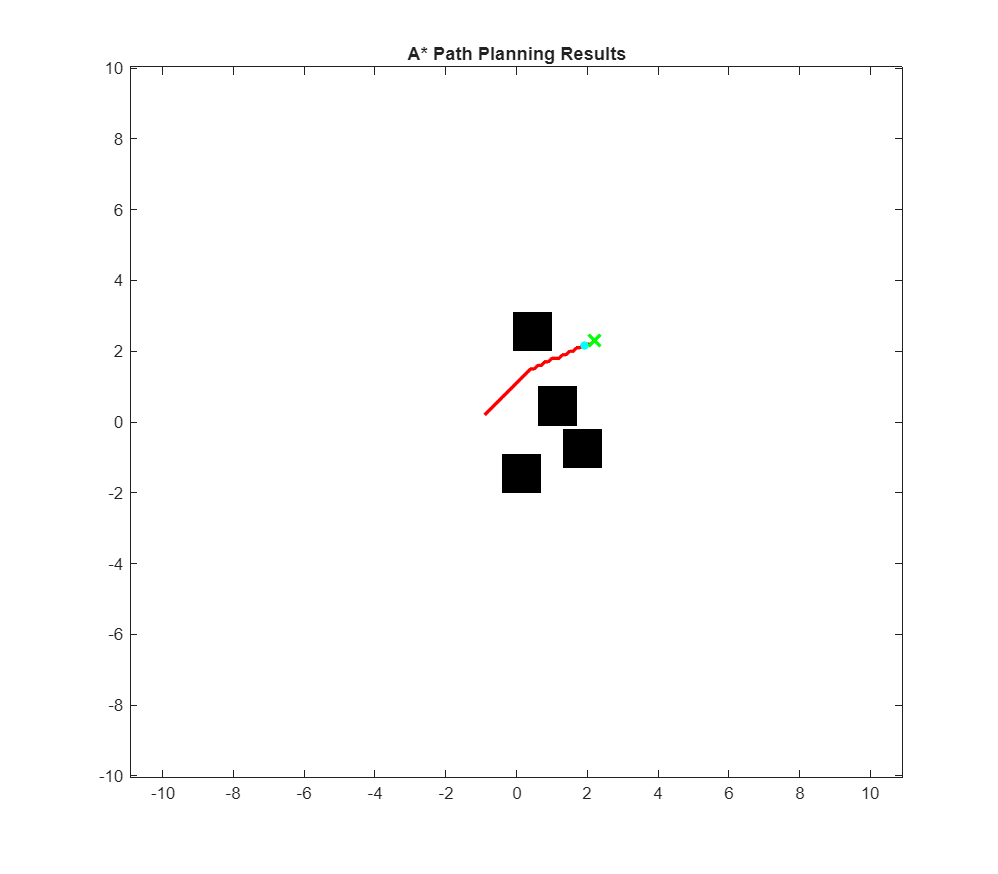

MISSION SUCCESS: GOAL REACHED!


Mission Finished.


system(['start "" "' exePath '"']);
pause(4); 

client = RemoteAPIClient();
sim = client.getObject('sim');

%% 2. LOAD SCENE
try
    disp('Cleaning up previous session...');
    sim.stopSimulation();
    while sim.getSimulationState() ~= sim.simulation_stopped, pause(0.1); end
    
    disp(['Loading Scene: ' sceneFile]);
    if isfile(sceneFile), sim.loadScene(sceneFile); end
    pause(1);

    % Handles
    robot  = sim.getObject('/summit_xl');
    goal   = sim.getObject('/Goal'); 
    
    % Wheel Handles (Robust Check)
    try
        wheels = [sim.getObject('/summit_xl_front_left_wheel'), ...
                  sim.getObject('/summit_xl_front_right_wheel'), ...
                  sim.getObject('/back_left_wheel'), ...
                  sim.getObject('/back_right_wheel')];
    catch
        wheels = [sim.getObject('/summit_xl/front_left_wheel_joint'), ...
                  sim.getObject('/summit_xl/front_right_wheel_joint'), ...
                  sim.getObject('/summit_xl/back_left_wheel_joint'), ...
                  sim.getObject('/summit_xl/back_right_wheel_joint')];
    end

    %% 3. GEOMETRY MAPPING
    disp('Generating Map from Object Coordinates...');
    
    mapSize = 20;        
    mapRes  = 0.1;       
    gridN   = round(mapSize / mapRes);
    
    occupancyGrid = true(gridN, gridN); 
    targetNames = {'Cuboid', 'Cylinder'};
    scanLimit = 20; 
    
    for t = 1:length(targetNames)
        baseName = targetNames{t};
        for k = 0:scanLimit
            if k == -1, objName = ['/' baseName];
            else, objName = sprintf('/%s[%d]', baseName, k); end
            try
                hObj = sim.getObject(objName);
                pos = sim.getObjectPosition(hObj, -1);
                if iscell(pos), pos = cell2mat(pos); end
                x = pos(1); y = pos(2);
                c = round((x + mapSize/2) / mapRes);
                r = round((y + mapSize/2) / mapRes);
                
                % INFLATION: 0.5m radius
                radius = 5; 
                r_start = max(1, r - radius); r_end = min(gridN, r + radius);
                c_start = max(1, c - radius); c_end = min(gridN, c + radius);
                occupancyGrid(r_start:r_end, c_start:c_end) = false;
            catch
                continue;
            end
        end
    end

    %% 4. A* PATH PLANNING
    disp('Planning Path (A*)...');
    
    rPos = sim.getObjectPosition(robot, -1);
    gPos = sim.getObjectPosition(goal, -1);
    if iscell(rPos), rPos=cell2mat(rPos); end
    if iscell(gPos), gPos=cell2mat(gPos); end
    
    startNode = world2grid(rPos(1), rPos(2), mapSize, mapRes);
    goalNode  = world2grid(gPos(1), gPos(2), mapSize, mapRes);
    
    pathIdx = a_star(occupancyGrid, startNode, goalNode);
    
    if isempty(pathIdx)
        error('No path found! Check obstacles.');
    end
    
    [pathR, pathC] = ind2sub(size(occupancyGrid), pathIdx);
    pathWorld = grid2world(pathR, pathC, mapSize, mapRes);

    % =============================================================
    % FORCE EXTERNAL PLOT WINDOW
    % =============================================================
    set(0, 'DefaultFigureWindowStyle', 'normal'); 
    f = figure('Name', 'Summit-XL Navigation Plan', ...
               'WindowStyle', 'normal', ... 
               'Color', 'w', ...
               'Position', [100, 100, 800, 700]);
    set(f, 'Visible', 'on');
    
    imagesc([-mapSize/2 mapSize/2], [-mapSize/2 mapSize/2], occupancyGrid);
    colormap gray; hold on; axis equal; set(gca, 'YDir', 'normal');
    plot(pathWorld(:,1), pathWorld(:,2), 'r-', 'LineWidth', 2);
    title('A* Path Planning Results');
    shg; drawnow;

    %% 5. NAVIGATION (EXACT PID)
    disp('Starting Navigation...');
    sim.setStepping(true);
    sim.startSimulation();
    
    % --- SUMMIT XL PARAMETERS ---
    v_lin = 0.1;          
    d = 0.73485;          
    r_wheel = 0.117345;   
    
    % --- PID GAINS ---
    Kp = 0.250; Ki = 0.0002; Kd = 0.001;
    LastError = 0; Integral = 0;
    
    currIdx = 1;
    lookahead = 0.6; 
    
    hRob = plot(rPos(1), rPos(2), 'c.', 'MarkerSize', 15);
    hTarget = plot(rPos(1), rPos(2), 'gx', 'MarkerSize', 10, 'LineWidth', 2);
    
    while ishandle(f)
        % 1. Get Robot Global State
        p = sim.getObjectPosition(robot, -1);
        if iscell(p), p=cell2mat(p); end
        
        % Update Visualization
        set(hRob, 'XData', p(1), 'YData', p(2)); 
        
        % 2. Check Goal Distance
        distToGoal = norm([p(1)-gPos(1), p(2)-gPos(2)]);
        if distToGoal < 0.3
            disp('MISSION SUCCESS: GOAL REACHED!');
            break;
        end
        
        % 3. Lookahead Selection
        while currIdx < size(pathWorld, 1)
            pt = pathWorld(currIdx, :);
            if norm([p(1)-pt(1), p(2)-pt(2)]) > lookahead
                break;
            end
            currIdx = currIdx + 1;
        end
        targetPt = pathWorld(currIdx, :);
        set(hTarget, 'XData', targetPt(1), 'YData', targetPt(2));
        drawnow limitrate;
        
        % 4. MATRIX FIX: Calculate Relative Position
        m = sim.getObjectMatrix(robot, -1);
        if iscell(m), m = cell2mat(m); end
        robotM = [reshape(m, [4, 3])'; 0 0 0 1];
        invRobM = inv(robotM);
        
        tWorld = [targetPt(1); targetPt(2); p(3); 1];
        tRel = invRobM * tWorld; 
        
        % 5. PID Calculation
        angle_error = atan2(tRel(2), tRel(1));
        
        DT = 0.05; 
        Derivative = (angle_error - LastError) / DT;
        Integral = Integral + (angle_error * DT);
        
        omega_robot = (Kp * angle_error) + (Kd * Derivative) + (Ki * Integral);
        
        LastError = angle_error;
        
        % 6. Compute Wheel Velocities
        v_right_lin = v_lin + (0.5 * d) * omega_robot;
        v_left_lin  = v_lin - (0.5 * d) * omega_robot;
        
        w_right = v_right_lin / r_wheel;
        w_left  = v_left_lin  / r_wheel;
        
        % 7. Actuate
        sim.setJointTargetVelocity(wheels(1), w_left);   
        sim.setJointTargetVelocity(wheels(3), w_left);   
        sim.setJointTargetVelocity(wheels(2), -w_right); 
        sim.setJointTargetVelocity(wheels(4), -w_right); 
        
        sim.step();
    end
    
    sim.stopSimulation();
    disp('Mission Finished.');
    
catch ME
    warning('Error: %s', ME.message);
    if exist('sim','var'), sim.stopSimulation(); end
end


%% HELPERS
function pathIdx = a_star(gridMap, startNode, goalNode)
    [rows, cols] = size(gridMap);
    [X, Y] = meshgrid(1:cols, 1:rows);
    [gr, gc] = ind2sub([rows, cols], goalNode);
    H = sqrt((X - gc).^2 + (Y - gr).^2);
    
    gScore = inf(rows, cols); gScore(startNode) = 0;
    fScore = inf(rows, cols); fScore(startNode) = H(startNode);
    cameFrom = zeros(rows, cols);
    openSet = [fScore(startNode), startNode];
    closedSet = false(rows, cols);
    pathIdx = [];
    
    while ~isempty(openSet)
        [~, minIdx] = min(openSet(:, 1));
        current = openSet(minIdx, 2);
        openSet(minIdx, :) = [];
        if current == goalNode
            pathIdx = current;
            while cameFrom(current) ~= 0
                current = cameFrom(current);
                pathIdx = [current; pathIdx]; %#ok<AGROW>
            end
            return;
        end
        closedSet(current) = true;
        [cr, cc] = ind2sub([rows, cols], current);
        neighbors = [cr-1, cc; cr+1, cc; cr, cc-1; cr, cc+1; cr-1, cc-1; cr-1, cc+1; cr+1, cc-1; cr+1, cc+1];
        for i = 1:8
            nr = neighbors(i, 1); nc = neighbors(i, 2);
            if nr>0 && nr<=rows && nc>0 && nc<=cols && gridMap(nr, nc) && ~closedSet(nr, nc)
                t_g = gScore(current) + norm([nr-cr, nc-cc]);
                nIdx = sub2ind([rows, cols], nr, nc);
                if t_g < gScore(nIdx)
                    cameFrom(nIdx) = current;
                    gScore(nIdx) = t_g;
                    fScore(nIdx) = t_g + H(nIdx);
                    if ~ismember(nIdx, openSet(:,2))
                        openSet = [openSet; fScore(nIdx), nIdx]; %#ok<AGROW>
                    else
                        openSet(openSet(:,2)==nIdx, 1) = fScore(nIdx);
                    end
                end
            end
        end
    end
end
function idx = world2grid(x, y, mapSize, res)
    c = max(1, min(round((x + mapSize/2) / res), round(mapSize/res)));
    r = max(1, min(round((y + mapSize/2) / res), round(mapSize/res)));
    idx = sub2ind([round(mapSize/res), round(mapSize/res)], r, c);
end
function world = grid2world(r, c, mapSize, res)
    world = [(c * res) - mapSize/2, (r * res) - mapSize/2];
end

## Try Yourself: Graph Search on a Grid Map

This exercise shows how graph search algorithms are used for robot path planning on a grid map.

In mobile robotics, the environment is often represented as an **occupancy grid**, where:

- **0 → free space**

- **1 → obstacle**

The robot must find a collision-free path from a start cell to a goal cell.**Core Idea**

We convert the environment into a graph:

- each grid cell → a node 

- connections between cells → edges 

Path planning then becomes:

**Find the best path in the graph**

**Algorithms Compared**

This exercise compares three search strategies:

**1. A* (A-star)**

- Uses both cost and heuristic 

- Efficient and optimal (if heuristic is admissible) 

**2. Dijkstra**

- Uses only cost 

- Explores uniformly 

- Always optimal but slow 

**3. Greedy Best-First Search**

- Uses only heuristic 

- Moves toward goal aggressively 

- Fast but may be suboptimal 

**Heuristics Used**

The heuristic estimates distance to the goal:

- **Euclidean distance** → straight-line distance 

- **Manhattan distance** → grid-aligned distance 

- **Weighted Euclidean** → scaled (can break optimality) 

**What the Code Does**

At each iteration:

**1. Select Node**

The algorithm selects the node with lowest:

- A* → g + h 

- Dijkstra → g 

- Greedy → h 

**2. Expand Neighbors**

Each node connects to 8 neighbors:

- straight moves → cost = 1 

- diagonal moves → cost = √2 

**3. Update Costs**

If a better path is found:

- update cost 

- store parent 

**4. Visualization**

The plot shows:

- **Black cells** → obstacles 

- **Yellow cells** → explored nodes 

- **Blue cells** → frontier (open set) 

- **Magenta path** → final solution 

**What You Should Observe**

When you run different settings:

**A***

- balanced search 

- fewer nodes explored 

- optimal path 

**Dijkstra**

- explores everywhere 

- many nodes expanded 

- optimal but slow 

**Greedy**

- very fast 

- narrow search 

#### **Changing the Search Strategy**

#### Modify `searchType` to switch between algorithms:

#### `searchType = 'astar';      % A* (balanced, optimal)`

#### `searchType = 'dijkstra';   % Dijkstra (no heuristic, slow but optimal)`

#### `searchType = 'greedy';     % Greedy (fast, may be suboptimal)`

#### may give longer path

#### **Changing the Search Strategy**

#### Modify `searchType` to switch between algorithms:

#### `searchType = 'astar';      % A* (balanced, optimal)`

#### `searchType = 'dijkstra';   % Dijkstra (no heuristic, slow but optimal)`

#### `searchType = 'greedy';     % Greedy (fast, may be suboptimal)`

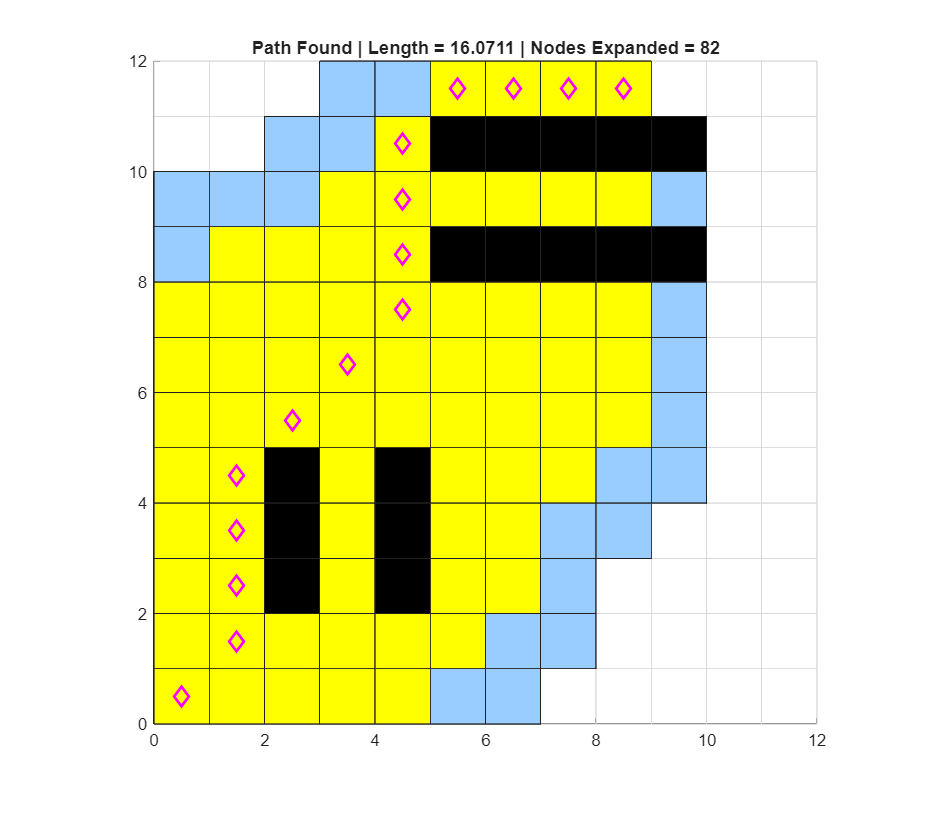


Baseline result:


Goal found       : 1


Path length      : 16.071


Nodes expanded   : 82


clc; clear; close all;

%% =========================================================
% FORCE EXTERNAL FIGURES (IMPORTANT)
%% =========================================================
com.mathworks.services.Prefs.setBooleanPref('LiveEditorFigureVisible', false);
set(0,'DefaultFigureWindowStyle','normal');

%% =========================================================
% PART 0: GRID SETUP
%% =========================================================
N = 12;

obstacles = [2,2;2,3;2,4;4,2;4,3;4,4;...
    5,8;6,8;7,8;8,8;9,8;...
    5,10;6,10;7,10;8,10;9,10];

occ = zeros(N,N);
for i=1:size(obstacles,1)
    occ(obstacles(i,1)+1,obstacles(i,2)+1) = 1;
end

start = [0 0];
goal  = [8 11];

% 8-connected motion
actions = [1,0;1,1;0,1;-1,1;-1,0;-1,-1;0,-1;1,-1];

%% =========================================================
% STUDENT CONTROLS
%% =========================================================
heuristicType = 'euclidean';   % 'euclidean', 'manhattan', 'weighted'
searchType    = 'astar';       % 'astar', 'greedy', 'dijkstra'

%% =========================================================
% FIGURE (EXTERNAL WINDOW)
%% =========================================================
f = figure('Name','Graph Search (A*, Greedy, Dijkstra)', ...
    'WindowStyle','normal', ...
    'Color','w', ...
    'Position',[100 100 750 650]);
set(f,'Visible','on');

axis equal
axis([0 N 0 N])
hold on

%% =========================================================
% DRAW GRID
%% =========================================================
for i=0:N
    for j=0:N
        rectangle('Position',[i j 1 1],'EdgeColor',[0.85 0.85 0.85]);
    end
end

%% =========================================================
% DRAW OBSTACLES
%% =========================================================
for k=1:size(obstacles,1)
    rectangle('Position',[obstacles(k,1) obstacles(k,2) 1 1],...
        'FaceColor','k');
end

%% =========================================================
% START & GOAL
%% =========================================================
plot(start(1)+0.5,start(2)+0.5,'go','MarkerSize',10,'LineWidth',2)
plot(goal(1)+0.5,goal(2)+0.5,'ro','MarkerSize',10,'LineWidth',2)

title(['Search: ',searchType,' | Heuristic: ',heuristicType])

%% =========================================================
% INITIALIZATION
%% =========================================================
OPEN = [];
CLOSED = [];

h_fun = @(p) computeHeuristic(p, goal, heuristicType);

node.pos = start;
node.g = 0;
node.h = h_fun(start);
node.f = computeF(node.g, node.h, searchType);
node.parent = [];

OPEN = node;

nodesExpanded = 0;
goalFound = false;

%% =========================================================
% MAIN SEARCH LOOP
%% =========================================================
while ~isempty(OPEN)

    % Select node with minimum f
    [~,idx] = min([OPEN.f]);
    current = OPEN(idx);
    OPEN(idx) = [];

    nodesExpanded = nodesExpanded + 1;

    % Add to CLOSED
    CLOSED = [CLOSED; current.pos];

    % Visualize explored node
    rectangle('Position',[current.pos 1 1],...
        'FaceColor',[1 1 0]); % yellow
    drawnow limitrate;

    % Goal check
    if all(current.pos == goal)
        goalNode = current;
        goalFound = true;
        break
    end

    %% Expand neighbors
    for i=1:size(actions,1)

        newPos = current.pos + actions(i,:);

        % Boundary check
        if any(newPos < 0) || any(newPos >= N)
            continue
        end

        % Obstacle check
        if occ(newPos(1)+1,newPos(2)+1) == 1
            continue
        end

        % Skip CLOSED
        if ismember(newPos,CLOSED,'rows')
            continue
        end

        % Cost computation
        stepCost = norm(actions(i,:));
        newNode.pos = newPos;
        newNode.g = current.g + stepCost;
        newNode.h = h_fun(newPos);
        newNode.f = computeF(newNode.g, newNode.h, searchType);
        newNode.parent = current;

        % Skip worse duplicates
        skip = false;
        for k=1:length(OPEN)
            if isequal(OPEN(k).pos,newPos) && OPEN(k).g <= newNode.g
                skip = true;
                break
            end
        end
        if skip
            continue
        end

        OPEN = [OPEN newNode];

        % Visualize frontier
        rectangle('Position',[newPos 1 1],...
            'FaceColor',[0.6 0.8 1]); % blue
    end

    pause(0.03);
end

%% =========================================================
% PATH RECONSTRUCTION
%% =========================================================
if goalFound

    path = [];
    node = goalNode;

    while ~isempty(node)
        path = [node.pos; path];
        node = node.parent;
    end

    % Draw path
    for i=1:size(path,1)
        plot(path(i,1)+0.5,path(i,2)+0.5,...
            'md','MarkerSize',8,'LineWidth',2)
    end

    % Path length
    L = 0;
    for i=2:size(path,1)
        L = L + norm(path(i,:) - path(i-1,:));
    end

    title(['Path Found | Length = ',num2str(L),...
        ' | Nodes Expanded = ',num2str(nodesExpanded)])

    fprintf('\nBaseline result:\n');
    fprintf('Goal found       : %d\n', goalFound);
    fprintf('Path length      : %.3f\n', L);
    fprintf('Nodes expanded   : %d\n', nodesExpanded);

else
    title('No Path Found')

    fprintf('\nBaseline result:\n');
    fprintf('Goal found       : %d\n', goalFound);
    fprintf('Path length      : not applicable\n');
    fprintf('Nodes expanded   : %d\n', nodesExpanded);
end


%% =========================================================
% FUNCTIONS
%% =========================================================

function h = computeHeuristic(p, goal, type)
    switch type
        case 'euclidean'
            h = norm(p - goal);

        case 'manhattan'
            h = sum(abs(p - goal));

        case 'weighted'
            h = 1.5 * norm(p - goal); % not admissible

        otherwise
            h = 0;
    end
end

function f = computeF(g, h, type)
    switch type
        case 'astar'
            f = g + h;

        case 'greedy'
            f = h;

        case 'dijkstra'
            f = g;
    end
end

**D* algorithm: **The D* algorithm is an incremental replanning version of A*. *Incremental* means that the algorithm reuses previous search effort instead of recomputing an entirely new plan whenever the environment changes. This makes D* particularly well suited for mobile robots operating in partially known or dynamic environments. D* updates only the nodes affected by the modifications in the map. A key characteristic of D* is that the search is usually reversed, it begins from the goal node and propagates cost information backward. This ensures that large portions of the previously computed solution remain valid and do not need to be recomputed.

# **Voronoi-Based Planning**

A Voronoi diagram splits space into regions based on proximity to obstacles.

Each point in free space is assigned to the closest obstacle.

The boundaries between regions form the Voronoi skeleton:

- points that are equidistant to two or more obstacles

- typically lie in the middle of free space corridors

These skeleton lines are useful because they keep the robot far from obstacles.

The Generalized Voronoi Diagram (GVD) is the set of points where: $d(x, O_i) = d(x,O_j), \quad i \neq j$

and this distance is locally minimal among all obstacles.

In simple terms: A point is on the GVD if it is equally close to at least two obstacles.

## Distance Transform

To compute this in a grid, we use a distance transform.


$$D(i,j) = \text{distance from cell } (i,j) \text{ to the nearest obstacle}$$


In discrete grids (like images), we approximate this using:

- 4-connected → Manhattan-like distance 

- 8-connected → closer to Euclidean distance 

## Brushfire Algorithm

The Brushfire algorithm computes a distance field by spreading a wave from all obstacles at once.

Think of it like lighting a fire at every obstacle. The fire spreads outward, and each cell records when the fire reaches it. That time step is its distance.

**State Variables**

For each grid cell $(i,j)$, we store:

- $D(i,j)$: distance from the nearest obstacle 

- $L(i,j)$: label of the nearest obstacle (which obstacle “owns” this cell) 

**Initialization**

All obstacle cells are the sources of the wave:


$$D(i,j) = 0 \quad \text{if } (i,j) \text{ is an obstacle}$$


Each connected obstacle component gets a unique label: $L(i,j) = k \quad \text{if } (i,j) \in O_k$�

All these obstacle cells are inserted into a queue. This means the wave starts simultaneously from all obstacles.

**Wave Propagation (Core Step)**

We process cells using a first-in-first-out queue.

At each step:

- Remove one cell from the queue 

- Visit its neighbors 

- Update their distance and label if needed 

For a neighbor $(n_i, n_j)$: $D(n_i, n_j) = D(i,j) + 1$, if this value is smaller than its current distance.

At the same time: $L(n_i, n_j) = L(i,j)$

So the neighbor inherits the label of the obstacle that reached it first.

Each obstacle grows its own region outward.

Where two regions meet, labels differ.

👉 This boundary is the Voronoi edge

# Try Yourself: Brushfire Distance Transform and GVD

This exercise computes:

- distance from obstacles 

- obstacle ownership 

- Voronoi skeleton (GVD)

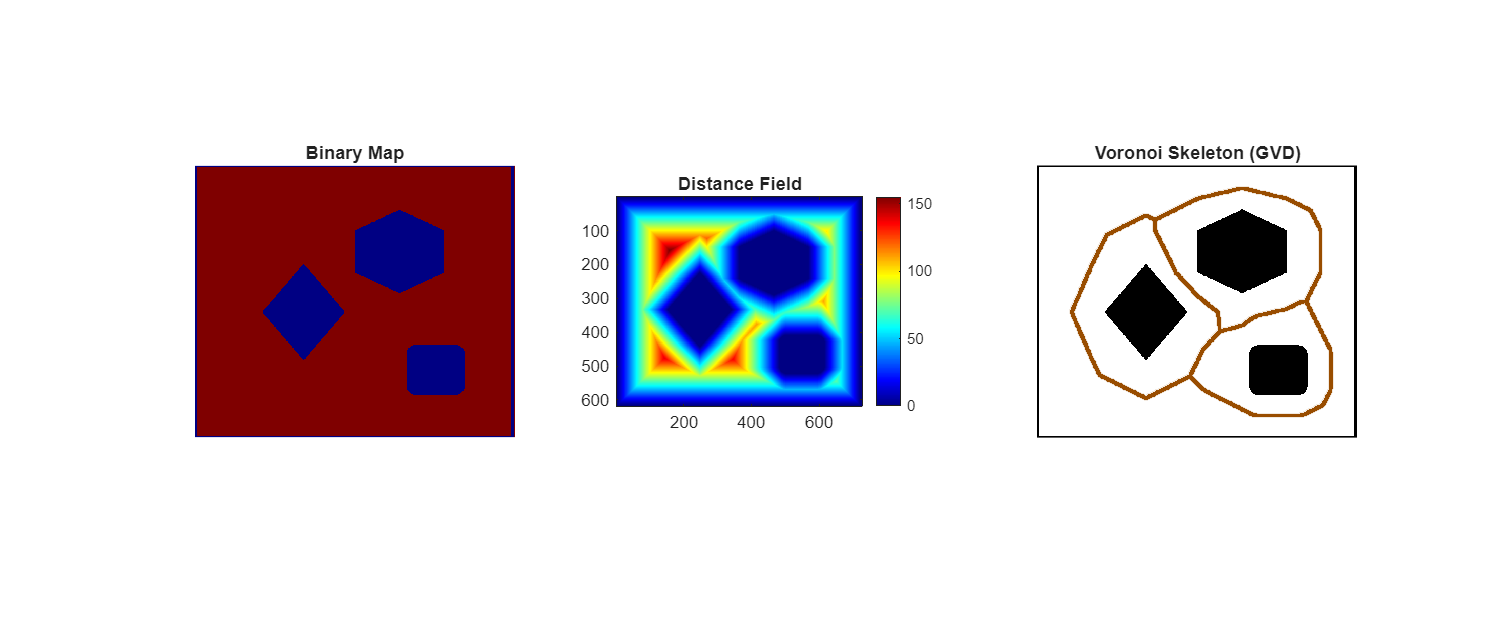

clc; clear; close all;

%% =========================================================
% FORCE EXTERNAL WINDOWS
%% =========================================================
com.mathworks.services.Prefs.setBooleanPref('LiveEditorFigureVisible', false);
set(0,'DefaultFigureWindowStyle','normal');

%% =========================================================
% 1. READ AND BINARIZE IMAGE
%% =========================================================

% Use current folder (most reliable for teaching)
imgPath = 'env.bmp';

if ~isfile(imgPath)
    error(['env.bmp not found.\nPlace it in this folder:\n' pwd]);
end

I = imread(imgPath);

% Convert to grayscale if needed
if size(I,3) == 3
    I = rgb2gray(I);
end

% Convert to binary (logical)
I = imbinarize(I);

free = I;
[ny,nx] = size(free);

%% =========================================================
% 2. INITIALIZE DISTANCE + LABELS
%% =========================================================
dist  = inf(ny,nx);
label = zeros(ny,nx);

% ===== FIX: Preallocated queue =====
queue = zeros(ny*nx, 2);
head = 1;
tail = 0;

cc = bwconncomp(~free);
numObs = cc.NumObjects;

for k = 1:numObs
    pixels = cc.PixelIdxList{k};

    dist(pixels) = 0;
    label(pixels) = k;

    [r,c] = ind2sub([ny nx], pixels);

    % enqueue all obstacle pixels
    for p = 1:length(r)
        tail = tail + 1;
        queue(tail,:) = [r(p) c(p)];
    end
end

%% =========================================================
% 3. BRUSHFIRE PROPAGATION (4-CONNECTED)
%% =========================================================
nbr = [0 1;1 0;0 -1;-1 0];

while head <= tail

    cell_rc = queue(head,:);
    head = head + 1;

    i = cell_rc(1);
    j = cell_rc(2);

    for n = 1:4
        ni = i + nbr(n,1);
        nj = j + nbr(n,2);

        if ni<1 || ni>ny || nj<1 || nj>nx
            continue;
        end

        if free(ni,nj)

            newDist = dist(i,j) + 1;

            if newDist < dist(ni,nj)
                dist(ni,nj) = newDist;
                label(ni,nj) = label(i,j);

                % enqueue
                tail = tail + 1;
                queue(tail,:) = [ni nj];
            end

        end
    end
end

%% =========================================================
% 4. EXTRACT GVD
%% =========================================================
GVD = false(ny,nx);

for i = 2:ny-1
    for j = 2:nx-1

        if free(i,j)

            for n = 1:4
                ni = i + nbr(n,1);
                nj = j + nbr(n,2);

                if label(ni,nj) ~= label(i,j)
                    GVD(i,j) = true;
                    break;
                end
            end

        end
    end
end

%% =========================================================
% 5. VISUALIZATION (FORCED EXTERNAL WINDOW)
%% =========================================================
f = figure('Name','Brushfire + GVD', ...
    'WindowStyle','normal', ...
    'Color','w', ...
    'Position',[100 100 1200 500], ...
    'Visible','off');   % create first (hidden)

set(f,'Visible','on'); % force display

subplot(1,3,1);
imshow(free);
title('Binary Map');

subplot(1,3,2);
imagesc(dist);
axis image;
colormap jet;
colorbar;
title('Distance Field');

subplot(1,3,3);
imshow(free); hold on;
[row,col] = find(GVD);
plot(col,row,'.','Color',[0.6 0.3 0],'MarkerSize',6);
title('Voronoi Skeleton (GVD)');


drawnow;   % ensure rendering


## Visibility Graph Planning

In contrast to Voronoi-based planning, which maximizes safety, the **visibility graph** focuses on finding the **shortest path** in environments with polygonal obstacles.

**Core Idea**

We construct a graph where:

- Nodes = obstacle vertices + start + goal 

- Edges = straight-line connections that do not intersect obstacles 

Then we run a shortest-path algorithm (A*) on this graph.

What is “Visibility”?

Two points are visible if:

- the straight line between them lies entirely in free space 

- it does not intersect any obstacle 

**Graph Construction**

We test every pair of vertices:

- Check if the midpoint lies inside an obstacle 

- Check if the line intersects any obstacle edge 

If both pass → add an edge

**A* on Visibility Graph**

Once the graph is built:

- edges are weighted by Euclidean distance 

- A* finds the shortest path

clc; clear; close all;

%% =========================================================
% FORCE EXTERNAL WINDOWS
%% =========================================================
com.mathworks.services.Prefs.setBooleanPref('LiveEditorFigureVisible', false);
set(0,'DefaultFigureWindowStyle','normal');

%% =========================================================
% DEFINE OBSTACLES
%% =========================================================
obs1 = [10,10;30,10;30,30];
obs2 = [40,30;50,40;30,60;20,50];
obs3 = [60,30;80,10;90,40;50,50];

obstacles = {obs1, obs2, obs3};

%% =========================================================
% FIGURE (EXTERNAL)
%% =========================================================
f = figure('Name','Visibility Graph + A*', ...
    'WindowStyle','normal', ...
    'Color','w', ...
    'Position',[100 100 700 700], ...
    'Visible','off');

set(f,'Visible','on'); hold on;
axis([0 100 0 100]);
axis equal; grid on;

for k = 1:length(obstacles)
    fill(obstacles{k}(:,1), obstacles{k}(:,2), ...
        'r','FaceAlpha',0.4,'EdgeColor','k');
end

%% =========================================================
% START & GOAL
%% =========================================================
vstart = [0,0];
vgoal  = [100,100];

plot(vstart(1),vstart(2),'go','MarkerSize',8,'LineWidth',2);
plot(vgoal(1),vgoal(2),'mo','MarkerSize',8,'LineWidth',2);

vertices = [obs1; obs2; obs3; vstart; vgoal];

%% =========================================================
% OBSTACLE EDGES
%% =========================================================
obsEdges = [];

for k = 1:length(obstacles)
    poly = obstacles{k};
    n = size(poly,1);
    for i = 1:n
        p1 = poly(i,:);
        p2 = poly(mod(i,n)+1,:);
        obsEdges = [obsEdges; p1 p2];
    end
end

%% =========================================================
% VISIBILITY GRAPH
%% =========================================================
edgesVG = [];

for i = 1:size(vertices,1)
    for j = i+1:size(vertices,1)

        v = vertices(i,:);
        w = vertices(j,:);

        mid = (v + w)/2;
        if pointInsideAnyObstacle(mid, obstacles)
            continue;
        end

        visible = true;

        for e = 1:size(obsEdges,1)

            p1 = obsEdges(e,1:2);
            p2 = obsEdges(e,3:4);

            if isequal(v,p1)||isequal(v,p2)||...
               isequal(w,p1)||isequal(w,p2)
                continue;
            end

            if segmentsIntersect(v,w,p1,p2)
                visible = false;
                break;
            end
        end

        if visible
            edgesVG = [edgesVG; i j];
        end
    end
end

%% =========================================================
% PLOT GRAPH
%% =========================================================
for k = 1:size(edgesVG,1)
    v1 = vertices(edgesVG(k,1),:);
    v2 = vertices(edgesVG(k,2),:);
    plot([v1(1) v2(1)], [v1(2) v2(2)], 'k');
end

plot(vertices(:,1), vertices(:,2), 'bo','MarkerFaceColor','b');

%% =========================================================
% A* SEARCH
%% =========================================================
N = size(vertices,1);
adj = cell(N,1);
cost = cell(N,1);

for k = 1:size(edgesVG,1)
    i = edgesVG(k,1);
    j = edgesVG(k,2);
    d = norm(vertices(i,:) - vertices(j,:));

    adj{i} = [adj{i} j];
    cost{i} = [cost{i} d];

    adj{j} = [adj{j} i];
    cost{j} = [cost{j} d];
end

startIdx = find(ismember(vertices, vstart, 'rows'));
goalIdx  = find(ismember(vertices, vgoal, 'rows'));

gScore = inf(N,1);
fScore = inf(N,1);

gScore(startIdx) = 0;
h = @(i) norm(vertices(i,:) - vertices(goalIdx,:));
fScore(startIdx) = h(startIdx);

openSet = startIdx;
cameFrom = zeros(N,1);

while ~isempty(openSet)

    [~, idxMin] = min(fScore(openSet));
    current = openSet(idxMin);

    if current == goalIdx
        break;
    end

    openSet(idxMin) = [];
    neighbors = adj{current};

    for k = 1:length(neighbors)
        neighbor = neighbors(k);
        tentative_g = gScore(current) + cost{current}(k);

        if tentative_g < gScore(neighbor)

            cameFrom(neighbor) = current;
            gScore(neighbor) = tentative_g;
            fScore(neighbor) = tentative_g + h(neighbor);

            if ~ismember(neighbor, openSet)
                openSet = [openSet; neighbor];
            end
        end
    end
end

%% =========================================================
% PATH
%% =========================================================
path = goalIdx;

while path(1) ~= startIdx
    path = [cameFrom(path(1)); path];
end

for k = 1:length(path)-1
    v1 = vertices(path(k),:);
    v2 = vertices(path(k+1),:);
    plot([v1(1) v2(1)], [v1(2) v2(2)], ...
        'g','LineWidth',3);
end

title('Visibility Graph + A* Shortest Path');
drawnow;
hold off;

%% =========================================================
% HELPERS
%% =========================================================
function flag = pointInsideAnyObstacle(pt, obstacles)
flag = false;
for k = 1:length(obstacles)
    poly = obstacles{k};
    [in,on] = inpolygon(pt(1),pt(2),poly(:,1),poly(:,2));
    if in && ~on
        flag = true; return;
    end
end
end

function flag = segmentsIntersect(p1,p2,q1,q2)
o1 = orientation(p1,p2,q1);
o2 = orientation(p1,p2,q2);
o3 = orientation(q1,q2,p1);
o4 = orientation(q1,q2,p2);
flag = (o1 ~= o2) && (o3 ~= o4);
end

function val = orientation(a,b,c)
val = sign((b(1)-a(1))*(c(2)-a(2)) - ...
           (b(2)-a(2))*(c(1)-a(1)));
end

# **Sampling-Based Algorithms**

In many complex, high-dimensional path-planning problems—such as manipulation with multi-jointed robot arms, molecular folding, protein docking, or other continuous configuration-space tasks, it becomes computationally infeasible to search the space exhaustively within practical time limits. Traditional heuristic search is often ineffective in these domains because:

- suitable heuristic functions may be unavailable or extremely difficult to design, and

- dimensionality reduction techniques typically fail, especially when the robot must respect dynamic, velocity, and acceleration constraints that cannot be violated for safety or feasibility.

In such cases, randomized search methods provide a powerful alternative. These methods sacrifice guaranteed optimality in exchange for dramatically improved scalability and computational efficiency. Instead of exploring the entire space systematically, they sample configurations randomly and build a structure (such as a tree or graph) that probabilistically converges toward a valid solution.

Randomized methods are particularly attractive because they:

- scale well to high-dimensional configuration spaces,

- handle complex motion constraints,

- avoid the need for carefully crafted heuristics, and

- offer probabilistic completeness**, **they will find a solution with probability approaching 1 as time increases, provided a solution exists.

**Two Main Approaches**

- **PRM (Probabilistic Roadmap)** → multi-query

- **RRT (Rapidly-Exploring Random Tree)** → single-query

**Probabilistic Roadmaps (PRM): **Probabilistic Roadmaps (PRMs) construct a graph-based representation of the free configuration space by randomly sampling valid configurations and connecting them through feasible paths. PRM separates the planning process into two phases: a roadmap construction phase and a query phase. In the construction phase, the algorithm samples a set of configurations in the free space and connects nearby configurations using a simple local planner, typically straight-line motion, provided the path between them is collision-free. This results in a roadmap that captures the connectivity of the free space. In the query phase, the start and goal configurations are added to the roadmap and connected to nearby nodes, after which a graph search algorithm such as A* or Dijkstra is used to compute a path. PRMs are particularly effective in static environments and multi-query scenarios, as the same roadmap can be reused for different start–goal pairs. As the number of samples increases, the roadmap more accurately represents the free space, and the probability of finding a valid path approaches one, reflecting the probabilistic completeness of the method.

### **Learning by Doing: Probabilistic Roadmap (PRM)**

This exercise helps you understand how PRM works in three stages:

- **Sampling** → generate valid nodes 

- **Roadmap construction** → connect neighbors 

- **Query (A*)** → find path 

**Core Idea**

PRM converts a continuous space into a graph:

- Nodes → sampled configurations 

- Edges → collision-free connections 

Then we solve:`Path Planning``=``Graph Search (A*)``\text{Path Planning} = \text{Graph Search (A*)}`Path Planning=Graph Search (A*)**What the Code Does**

At each stage:

**1. Sampling**

- Randomly generate points in free space 

- Reject points inside obstacles 

**2. Roadmap Construction**

- For each node: 

- Find nearest neighbors 

- Try connecting them 

- Add edge if collision-free 

**3. Query (A*)**

- Add start and goal 

- Connect them to roadmap 

- Run A* to find path

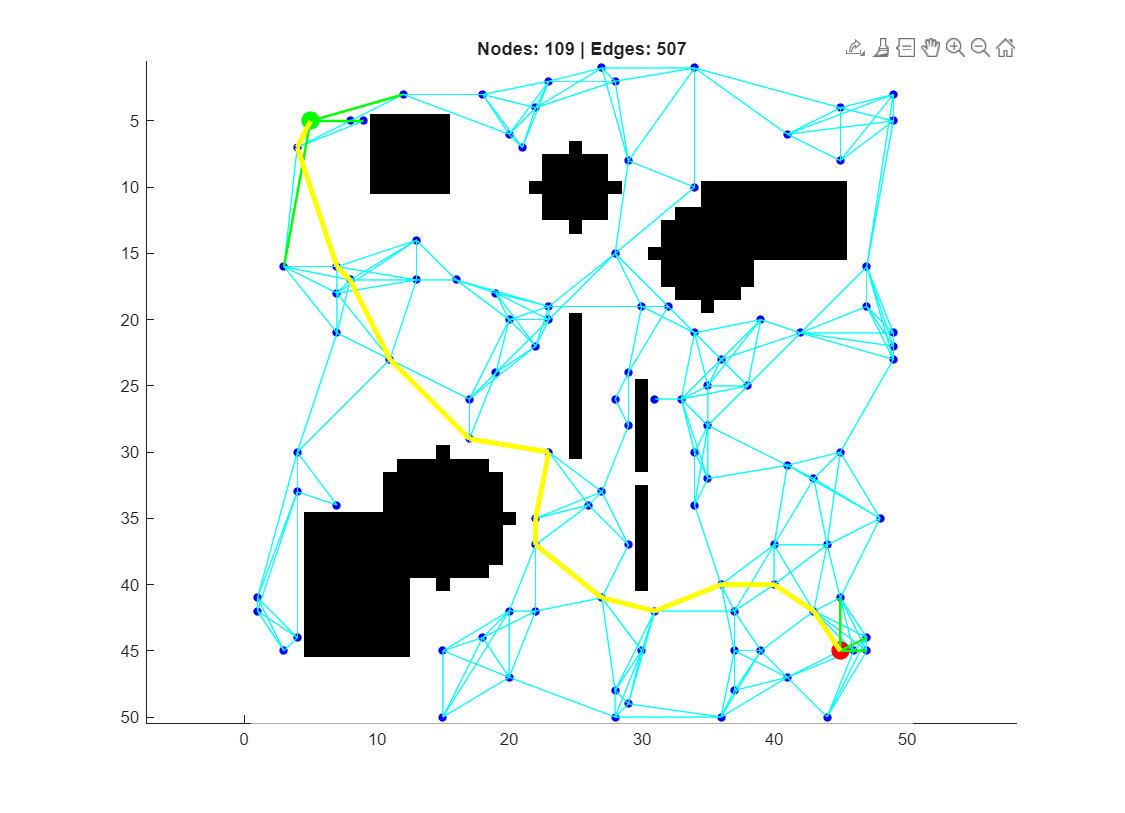

com.mathworks.services.Prefs.setBooleanPref('LiveEditorFigureVisible', false);
set(0,'DefaultFigureWindowStyle','normal');
clear; clc; close all force;

%% ===== ENVIRONMENT =====
grid = ones(50);

%% ===== ORIGINAL WALL =====
grid(20:30,25) = 0;

%% ===== ADDITIONAL RECTANGULAR OBSTACLES =====
grid(5:10,10:15) = 0;     % small block (top-left)
grid(35:45,5:12) = 0;     % large block (bottom-left)
grid(10:15,35:45) = 0;    % horizontal block (top-right)

%% ===== ADD A NARROW PASSAGE (IMPORTANT TEST) =====
grid(25:40,30) = 0;       % vertical wall
grid(32,30) = 1;          % small gap (hard for PRM)

%% ===== CIRCULAR OBSTACLES =====
[X,Y] = meshgrid(1:50,1:50);

% circle 1
circle1 = (X-15).^2 + (Y-35).^2 <= 5^2;
grid(circle1) = 0;

% circle 2
circle2 = (X-35).^2 + (Y-15).^2 <= 4^2;
grid(circle2) = 0;

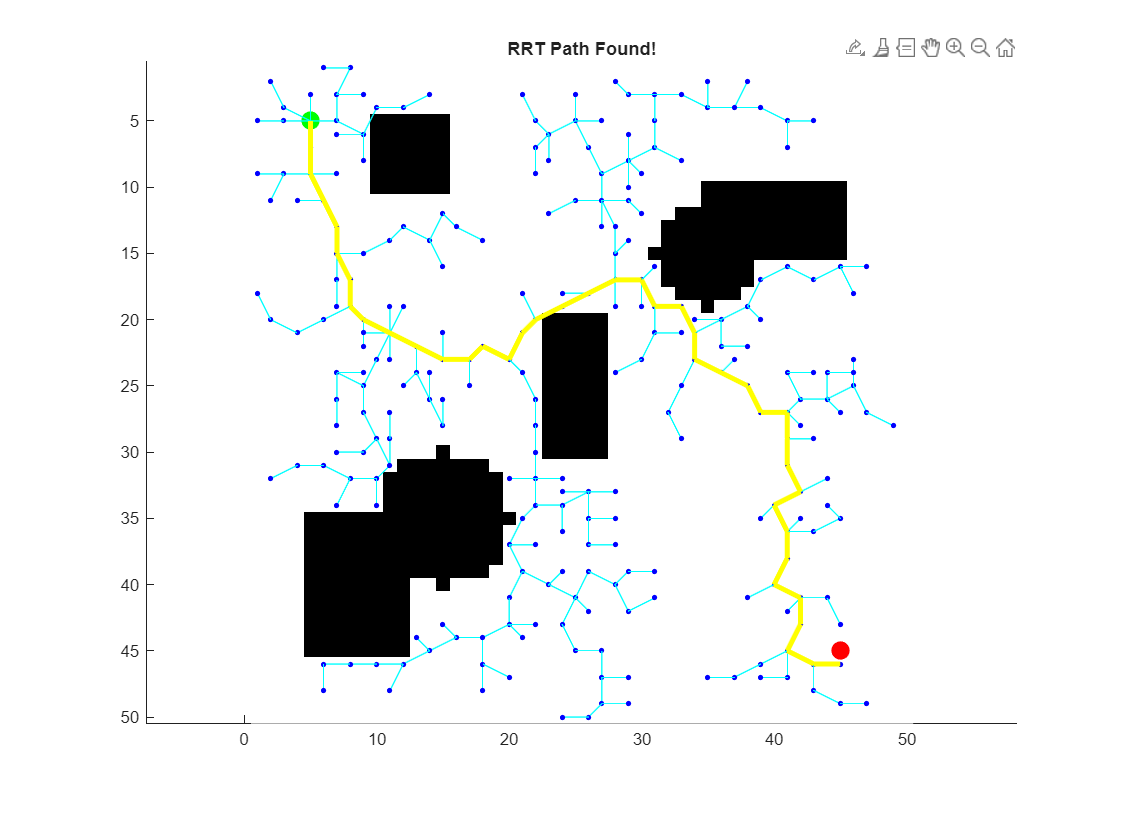


% circle 3 (smaller)
circle3 = (X-25).^2 + (Y-10).^2 <= 3^2;
grid(circle3) = 0;
start = [5 5];
goal  = [45 45];

num_samples = 120;   % 👉 tune
k_neighbors = 5;     % 👉 tune

nodes = [];
edges = [];

%% ===== FIGURE (EXTERNAL WINDOW) =====
f = figure('Name','PRM + A* (Animated)', ...
           'WindowStyle','normal', ...
           'Position',[100 100 900 650], ...
           'Color','w');
set(f,'Visible','on');

ax = axes('Parent',f);
hold(ax,'on'); 
axis(ax,'equal');

imagesc(ax,grid);
colormap(ax,gray);
set(ax,'YDir','reverse');

title(ax,'PRM: Sampling Phase');

%% =========================================================
%% 🔵 STEP 1: SAMPLING (ANIMATED)
%% =========================================================
for i = 1:num_samples
    
    p = [randi(50), randi(50)];
    
    if grid(p(1),p(2)) == 1
        nodes = [nodes; p];
        
        scatter(ax,p(2),p(1),25,'b','filled');
        
        title(ax,['Sampling Nodes: ', num2str(size(nodes,1))]);
        drawnow;
        pause(0.01);
    end
end

%% =========================================================
%% 🔗 STEP 2: ROADMAP CONSTRUCTION (ANIMATED)
%% =========================================================
title(ax,'Connecting Roadmap...');

for i = 1:size(nodes,1)
    
    dists = sum((nodes - nodes(i,:)).^2,2);
    [~,idx] = sort(dists);
    
    for j = 2:k_neighbors+1
        
        p1 = nodes(i,:);
        p2 = nodes(idx(j),:);
        
        % collision check
        line_pts = round([linspace(p1(1),p2(1),20)', ...
                          linspace(p1(2),p2(2),20)']);
        
        valid = true;
        for k = 1:size(line_pts,1)
            if grid(line_pts(k,1), line_pts(k,2)) == 0
                valid = false;
                break;
            end
        end
        
        if valid
            edges = [edges; i idx(j)];
            
            plot(ax,[p1(2) p2(2)], ...
                    [p1(1) p2(1)], ...
                 'c');
            
            drawnow;
            pause(0.002);
        end
    end
end

%% =========================================================
%% 🟢🔴 STEP 3: ADD START & GOAL
%% =========================================================
nodes = [nodes; start; goal];

start_idx = size(nodes,1)-1;
goal_idx  = size(nodes,1);

scatter(ax,start(2),start(1),120,'g','filled');
scatter(ax,goal(2),goal(1),120,'r','filled');

title(ax,'Connecting Start & Goal...');

% connect start & goal
for i = [start_idx goal_idx]
    
    dists = vecnorm(nodes - nodes(i,:),2,2);
    [~,idx] = sort(dists);
    
    for j = 2:k_neighbors+1
        
        p1 = nodes(i,:);
        p2 = nodes(idx(j),:);
        
        line_pts = round([linspace(p1(1),p2(1),20)', ...
                          linspace(p1(2),p2(2),20)']);
        
        if all(grid(sub2ind(size(grid), ...
             line_pts(:,1), line_pts(:,2))))
         
            edges = [edges; i idx(j)];
            
            plot(ax,[p1(2) p2(2)], ...
                    [p1(1) p2(1)], ...
                 'g','LineWidth',1.5);
            
            drawnow;
        end
    end
end

%% =========================================================
%% 🧠 STEP 4: BUILD GRAPH
%% =========================================================
N = size(nodes,1);
adj = cell(N,1);

for i = 1:size(edges,1)
    a = edges(i,1);

    b = edges(i,2);
    
    adj{a} = [adj{a}; b];
    adj{b} = [adj{b}; a];
end

%% =========================================================
%% ⭐ STEP 5: A* SEARCH
%% =========================================================
gScore = inf(N,1);
fScore = inf(N,1);
cameFrom = zeros(N,1);

gScore(start_idx) = 0;

H = vecnorm(nodes - nodes(goal_idx,:),2,2);
fScore(start_idx) = H(start_idx);

openSet = start_idx;
closedSet = false(N,1);

title(ax,'Running A* on Roadmap...');

while ~isempty(openSet)
    
    [~,i] = min(fScore(openSet));
    current = openSet(i);
    openSet(i) = [];
    
    if current == goal_idx
        break;
    end
    
    closedSet(current) = true;
    
    neighbors = adj{current};
    
    for k = 1:length(neighbors)
        n = neighbors(k);
        
        if closedSet(n), continue; end
        
        cost = norm(nodes(current,:) - nodes(n,:));
        tentative_g = gScore(current) + cost;
        
        if tentative_g < gScore(n)
            cameFrom(n) = current;
            gScore(n) = tentative_g;
            fScore(n) = gScore(n) + H(n);
            
            if ~ismember(n, openSet)
                openSet = [openSet; n];
            end
        end
    end
end

%% =========================================================
%% 🟡 STEP 6: PATH RECONSTRUCTION
%% =========================================================
path_idx = goal_idx;

while path_idx(1) ~= start_idx
    parent = cameFrom(path_idx(1));
    if parent == 0
        error('No path found!');
    end
    path_idx = [parent; path_idx];
end

path = nodes(path_idx,:);

%% =========================================================
%% 🎬 STEP 7: ANIMATE FINAL PATH
%% =========================================================
title(ax,'Final Path (PRM + A*)');

for i = 2:size(path,1)
    plot(ax, path(i-1:i,2), path(i-1:i,1), ...
         'y', 'LineWidth', 3);
    drawnow;
    pause(0.03);
end

%% =========================================================
%% ✅ FINAL INFO
%% =========================================================
title(ax, sprintf('Nodes: %d | Edges: %d', ...
      size(nodes,1), size(edges,1)));

**Rapidly-Exploring Random Trees (RRT):** Rapidly-Exploring Random Trees (RRTs) grow a search tree incrementally and online, requiring only an obstacle map rather than a precomputed graph or decomposition. The algorithm begins with an initial tree rooted at the start configuration (or even an empty seed) and successively expands this tree until a termination condition is met, such as reaching the goal or hitting a time limit.

At each iteration:

- A random configuration $q_{\text{rand}}$ is sampled from the free space.

- The nearest existing node in the tree, $q_{\text{rand}}$, is found using a suitable metric.

- A new configuration $q_{\text{new}}
$ is generated by moving from $q_{\text{near}}$ towards $q_{\text{rand}}$, typically by a fixed step size and using an appropriate robot motion model.

- If the path between $q_{\text{near}}$ and $q_{\text{new}}$ is collision-free, the new configuration is added to the tree as a new node.

This process tends to rapidly push the tree outward into unexplored regions of the configuration space, hence the name.

# Learning by Doing: Rapidly-Exploring Random Tree (RRT)

This exercise helps you understand how RRT explores space by **growing a tree from the start toward random samples**.**Core Idea**

RRT builds a tree incrementally:

- Start from initial node 

- Randomly sample space 

- Extend tree toward samples 

At each iteration:

**1. Random Sampling**

- Select a random point in space 

**2. Nearest Node**

- Find closest node in tree 

**3. Extension**

- Move a small step toward sample 

**4. Collision Check**

- Add node if valid 

**5. Repeat**

- Until goal is reached

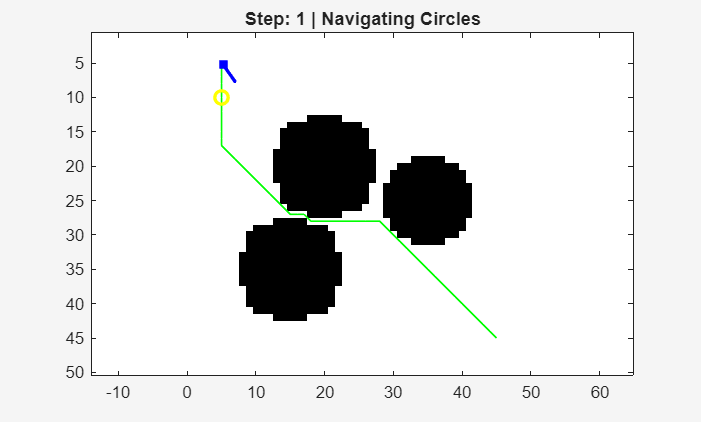

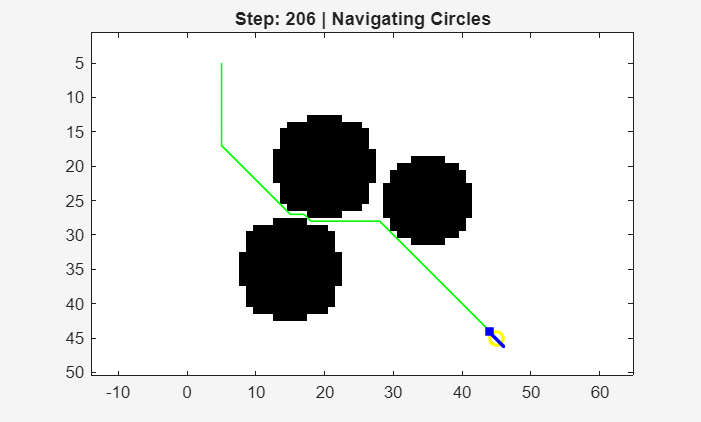

com.mathworks.services.Prefs.setBooleanPref('LiveEditorFigureVisible', false);
set(0,'DefaultFigureWindowStyle','normal');
clear; clc; close all force;

grid = ones(50);

% obstacles
grid(20:30,23:27) = 0;
grid(5:10,10:15) = 0;
grid(35:45,5:12) = 0;
grid(10:15,35:45) = 0;

[X,Y] = meshgrid(1:50,1:50);
grid((X-15).^2 + (Y-35).^2 <= 5^2) = 0;
grid((X-35).^2 + (Y-15).^2 <= 4^2) = 0;

start = [5 5];
goal  = [45 45];

% ===== TUNABLE PARAMETERS =====
step_size = 2;        % 👉 step length
max_iter  = 1000;     % 👉 iterations
goal_radius = 2;      % 👉 goal threshold

nodes = start;
parent = 0;

f = figure('Name','RRT (Animated)', ...
           'WindowStyle','normal', ...
           'Position',[100 100 900 650], ...
           'Color','w');
set(f,'Visible','on');
ax = axes('Parent',f);
hold(ax,'on'); axis(ax,'equal');

imagesc(ax,grid);
colormap(ax,gray);
set(ax,'YDir','reverse');

scatter(ax,start(2),start(1),120,'g','filled');
scatter(ax,goal(2),goal(1),120,'r','filled');

title(ax,'RRT: Growing Tree...');

goal_reached = false;

for iter = 1:max_iter
    
    % 1. Random sample
    q_rand = [randi(50), randi(50)];
    
    % 2. Find nearest node
    dists = sum((nodes - q_rand).^2,2);
    [~,idx] = min(dists);
    q_near = nodes(idx,:);
    
    % 3. Step toward sample
    dir = q_rand - q_near;
    dir = dir / (norm(dir)+1e-6);
    
    q_new = round(q_near + step_size * dir);
    
    % bounds check
    if any(q_new < 1) || any(q_new > 50)
        continue;
    end
    
    % 4. collision check
    if grid(q_new(1),q_new(2)) == 1
        
        nodes = [nodes; q_new];
        parent = [parent; idx];
        
        % draw edge
        plot(ax,[q_near(2) q_new(2)], ...
                [q_near(1) q_new(1)], 'c');
        
        % draw node
        scatter(ax,q_new(2),q_new(1),10,'b','filled');
        
        drawnow;
        
        % 5. check goal
        if norm(q_new - goal) < goal_radius
            goal_reached = true;
            goal_idx = size(nodes,1);
            break;
        end
    end
end

if goal_reached
    
    title(ax,'RRT Path Found!');
    
    path = nodes(goal_idx,:);
    cur = goal_idx;
    
    while cur ~= 1
        cur = parent(cur);
        path = [nodes(cur,:); path];
    end
    
    % animate path
    for i = 2:size(path,1)
        plot(ax,path(i-1:i,2),path(i-1:i,1), ...
             'y','LineWidth',3);
        drawnow;
        pause(0.03);
    end
    
else
    title(ax,'Goal Not Reached (Try tuning parameters)');
end

# **Obstacle avoidance**

Local obstacle avoidance concerns the real-time modification of a robot’s trajectory based on its sensor observations during motion. The robot’s resulting behavior depends on two factors:

- **Current (or recent) sensor readings**, which indicate nearby obstacles, and

- **The relative position of the goal**, which provides a general direction of desired motion.

The obstacle-avoidance methods presented in this section differ in their assumptions about the availability of a global map and the robot’s localization accuracy. However, they are all considered obstacle-avoidance algorithms because local sensor information plays a central role in determining the robot’s immediate trajectory.

**Bug algorithms: **The Bug algorithms are among the simplest possible methods for local obstacle avoidance. Their core idea is intuitive, "**When the robot encounters an obstacle, it follows the obstacle’s boundary until it can resume motion toward the goal." **Despite their simplicity  and sometimes extreme inefficiency, Bug algorithms possess strong theoretical guarantees that they will reach the goal whenever a path exists. 

## Bug 1

In Bug 1, when the robot meets an obstacle, it fully circumnavigates the obstacle’s boundary once. While doing so, it monitors the point on the boundary that is closest to the goal. After completing the loop, the robot returns to that point and departs toward the goal. This strategy guarantees completeness but is often highly inefficient, since the robot must trace the entire perimeter of every encountered obstacle.

## Bug 2

Bug 2 achieves better performance in many cases. Upon hitting an obstacle, the robot begins following the obstacle’s boundary (wall-following). However, it does not complete a full loop. Instead, it leaves the boundary as soon as it finds a point from which it can move straight toward the goal without immediate collision.

This results in significantly shorter travel distances compared to Bug 1. Nevertheless, contrived environments can still cause arbitrarily inefficient motions, so Bug 2 remains suboptimal.

## TangentBug

A more advanced variant is TangentBug, which enhances efficiency by using range-sensor information to construct a local tangent graph (LTG). With the LTG, the robot can:

- choose more informed directions during boundary following,

- take shortcuts along tangential directions, and

- switch back to goal-seeking earlier when safe.

In many simple environments, TangentBug can closely approach globally optimal paths, significantly outperforming the simpler Bug methods.

**Vector Field Histogram (VFH): **A major weakness of Bug-type obstacle avoidance methods is that they base decisions solely on instantaneous sensor readings. This makes them vulnerable in situations where the robot's immediate sensor data does not reveal enough information for robust motion decisions. VFH overcomes this limitation by constructing and updating a local occupancy grid,a small robot-centered map derived from recent sensor readings. From this local occupancy grid, VFH computes a **polar histogram**, in which the x-axis represents direction (angle $\alpha $) relative to the robot, the y-axis represents the probability $P$ of an obstacle in that direction, as inferred from the local occupancy grid. Using this histogram, the algorithm identifies steering directions that avoid obstacles while keeping the robot oriented toward the goal. The VFH algorithm proceeds in two stages:

- **Identify feasible openings** in the polar histogram, continuous angular sectors where the robot can physically pass.

- **Evaluate each opening** using a cost function and choose the opening with the lowest cost.

The cost function $G$ is given by $G = a \cdot \text{target\_direction} + b \cdot \text{wheel\_orientation} + c \cdot \text{previous\_direction}$, where

- **target_direction** measures alignment with the direction to the goal,

- **wheel_orientation** is the angular difference between the candidate steering direction and the robot’s current wheel heading,

- **previous_direction** penalizes sharp deviations from the last chosen direction (encouraging smooth motion).

- The parameters $a,b,c$ adjust the robot’s behavior. 

**The bubble band technique: **A bubble is defined as the largest local region of free space surrounding a given robot configuration within which the robot can move without collision. The bubble is computed using a simplified geometric model of the robot together with range information from the robot’s map. Even with simple geometric approximations, the bubble’s shape can reflect the robot’s actual physical dimensions and orientation. Once individual bubbles are computed, they are arranged along the robot’s planned path, forming a bubble band, a connected sequence of overlapping bubbles extending from the start to the goal. Constructing a bubble band requires both:

- a global map, and

- a global path planner to provide an initial trajectory.

After the initial path is obtained, the bubble band is generated, and the trajectory is then adjusted based on two kinds of forces:

- **External forces** originating from obstacles in the environment (as represented by the free-space geometry), and

- **Internal forces** that act like tension in a string, attempting to minimize slack between adjacent bubbles.

These forces iteratively deform the path so that the robot’s motion remains smooth and consistent with the available free space. A final smoothing stage ensures that the resulting path is dynamically feasible and varies smoothly as the robot progresses.

**Curvature velocity techniques (CVM): **CVM operates in velocity space, defined by:

- translational velocity $v$, and

- rotational velocity $\omega$.

For any pair $\left(v,\omega \right)$, the robot’s trajectory is assumed to be an arc of a circle with curvature $c = \frac{\omega}{v}$.

Thus, obstacle avoidance becomes the task of determining which pairs $\left(v,\omega \right)$ produce safe, feasible trajectories. Two broad categories of constraints define the admissible velocity space:

**(a) Robot constraints**

These arise from kinematic and dynamic limits: $v_{\min} < v < v_{\max}, \quad  \omega_{\min} < \omega < \omega_{\max},$ along with limits on acceleration and deceleration.

**(b) Obstacle constraints**

Obstacles in the Cartesian map are projected into velocity space. For any candidate curvature $c$, the distance from the robot to an obstacle along the corresponding circular arc is computed. If the robot would collide with the obstacle at that curvature, then the corresponding $\left(v,\omega \right)$ pair is forbidden. Only curvatures in the range $[c_{\min}, c_{\max}]$ need to be evaluated, since this interval contains all physically feasible robot trajectories.

To achieve **real-time performance**, CVM uses several approximations:

- Obstacles are modeled as circles.

- Each obstacle contour is discretized into a small number of angular intervals.

- Between interval endpoints, the distance-to-collision is treated as constant.

The robot evaluates candidate velocities only within the subset of velocity space that is:

- kinematically feasible,

- dynamically allowed, and

- obstacle-free.

An objective function then selects the optimal velocity pair $\left(v,\omega \right)$, balancing safety, progress toward the goal, and smoothness. A key advantage of CVM is that it naturally incorporates vehicle dynamics. However, the circular-obstacle approximation can be problematic in cluttered environments with elongated or non-uniform obstacles. Moreover, because CVM relies solely on instantaneous sensor data and no global knowledge, it may suffer from local minima. 

**Lane Curvature Method (LCM):  **In CVM the assumption that the robot moves along a single, fixed arc is overly restrictive. LCM takes a more flexible approach than CVM by computing a set of candidate lanes:

- Each lane is a feasible path corridor extending forward from the robot.

- Lane quality depends on both length (how far the robot can proceed) and width (distance to nearby obstacles).

The algorithm then evaluates all lanes using a cost function and selects the **best lane**, typically the one offering the safest and most promising passage forward. By considering multiple forward-looking motion corridors rather than a single curvature arc, LCM improves robustness in structured indoor environments, particularly in places where CVM tends to get stuck, such as corridor intersections and doorways. 

**Dynamic Window Approaches: **Another effective technique for incorporating the robot’s kinematic and dynamic constraints into obstacle avoidance is the dynamic window approach. This method relies on a simple but powerful dynamic model of the robot, from which it takes its name. Two major versions exist:

- the **local Dynamic Window Approach (DWA)** 

- the **Global Dynamic Window Approach (GDWA)**

Both methods operate in velocity space, directly evaluating feasible translational and rotational velocities rather than explicitly planning geometric paths.

 **Local Dynamic Window Approach: **In the local DWA, the robot’s motion is represented by circular arcs, each defined by a pair $\left(v,\omega \right)$, where:

- $v$ = translational velocity

- $\omega$ = angular velocity

The algorithm proceeds in three stages:

**(a) Constructing the dynamic window**

Given the robot’s current velocity and its acceleration limits, the dynamic window consists of all velocity pairs $\left(v,\omega \right)$ that the robot can achieve within the next control cycle. This window reflects the robot’s physical acceleration constraints.Because translational and rotational accelerations are treated as independent, the dynamic window has a rectangular shape in $\left(v,\omega \right)$-space.

**(b) Selecting admissible velocities**

Next, velocities that would inevitably lead to a collision are removed. A velocity pair $\left(v,\omega \right)$ is considered admissible only if the robot can brake to a stop before hitting an obstacle along the associated circular trajectory. This ensures collision-free motion, even at high speeds.

**(c) Selecting the optimal motion command**

An objective function evaluates all admissible velocities given by $O =  a \cdot \text{heading}(v, \omega) + b \cdot \text{velocity}(v, \omega) + c \cdot \text{dist}(v, \omega)$, where

- **heading**: measures alignment with the goal direction

- **velocity**: favors faster forward motion

- **dist**: maximizes clearance from nearby obstacles

## **Learning by Doing: Dynamic Window Approach (DWA)**

DWA is a **reactive local planner**.

Instead of planning a full path, it selects the **best velocity command at each step**.**Core Idea**

At each time step, DWA:

- Samples possible velocities `(``v``,``ω``)`

- Simulates short trajectories 

- Scores them based on: 

- goal direction 

- obstacle clearance 

- speed 

- Picks the best command 

`Best Control``= `$\arg\max (w_1 \cdot \text{goal} + w_2 \cdot \text{clearance} + w_3 \cdot \text{velocity})$

**What the Code Does**

At each iteration:

**1. Generate Velocity Samples**

- Linear velocity `v`

- Angular velocity `ω`

**2. Forward Simulation**

- Predict robot motion for short time 

**3. Evaluate Trajectory**

- Distance to goal 

- Distance to obstacles 

- Smoothness 

**4. Select Best Motion**

- Apply control 

- Move robot 

% DWA
set(0,'DefaultFigureWindowStyle','normal');

ans = "It guarantees that if a solution exists, the algorithm will find it; otherwise, it reports failure."

com.mathworks.services.Prefs.setBooleanPref('LiveEditorFigureVisible', true);
clear; clc; close all force;

%% =========================================================
%% ENVIRONMENT (CIRCULAR OBSTACLES)
%% =========================================================
grid_size = 50;
grid = ones(grid_size);

Right Answer



% Define 3 circles: [x, y, radius]

ans = "A location other than the goal where the attractive and repulsive forces cancel out to zero."

circles = [
    20, 20, 5;
    35, 25, 4;
    15, 35, 5
];

[X, Y] = meshgrid(1:grid_size, 1:grid_size);
for i = 1:size(circles, 1)

Right Answer


    cx = circles(i,1); cy = circles(i,2); cr = circles(i,3);
    grid((X-cx).^2 + (Y-cy).^2 <= cr^2) = 0;

ans = "A* uses a heuristic to estimate the cost-to-goal, guiding the search more efficiently."

end

% Inflation
robot_radius = 2;
inflated = grid;
[obs_r, obs_c] = find(grid == 0);
for k = 1:length(obs_r)
    r = obs_r(k); c = obs_c(k);

Right Answer


    r1 = max(1, r-robot_radius); r2 = min(grid_size, r+robot_radius);
    c1 = max(1, c-robot_radius); c2 = min(grid_size, c+robot_radius);
    inflated(r1:r2, c1:c2) = 0;
end
grid = inflated;

%% =========================================================
%% GLOBAL PATH (BFS)
%% =========================================================
start = [5, 5]; 
goal  = [45, 45];
q = [start];
parent = zeros(grid_size, grid_size, 2);
visited = false(grid_size, grid_size);
visited(start(2), start(1)) = true;

found = false;
while ~isempty(q)
    curr = q(1,:); q(1,:) = [];
    if norm(curr - goal) < 1.0, found = true; break; end
    dirs = [0 1; 0 -1; 1 0; -1 0; 1 1; 1 -1; -1 1; -1 -1];
    for d = 1:8
        next = curr + dirs(d,:);
        if next(1)>0 && next(1)<=50 && next(2)>0 && next(2)<=50
            if grid(next(2), next(1)) == 1 && ~visited(next(2), next(1))
                visited(next(2), next(1)) = true;
                parent(next(2), next(1), :) = curr;
                q = [q; next];
            end
        end
    end
end

% Backtrack waypoints
waypoints = goal;
curr = goal;
if found
    while any(parent(round(curr(2)), round(curr(1)), :) ~= 0)
        curr = squeeze(parent(round(curr(2)), round(curr(1)), :))';
        waypoints = [curr; waypoints];
    end
end

%% =========================================================
%% DWA INITIALIZATION
%% =========================================================
pos = start;
theta = atan2(goal(2)-start(2), goal(1)-start(1));
v_max = 1.5;
w_max = 1.5;
dt = 0.2;
wp_idx = 1;

f = figure(1); 
set(f, 'Visible', 'on');
ax = axes('Parent', f);

%% =========================================================
%% MAIN LOOP
%% =========================================================
for step = 1:600
    % Waypoint Selection
    if wp_idx < size(waypoints, 1)
        if norm(pos - waypoints(wp_idx,:)) < 3.0
            wp_idx = min(wp_idx + 5, size(waypoints, 1));
        end
    end
    current_target = waypoints(wp_idx, :);

    best_score = -inf;
    best_u = [0 0];
    
    % DWA Sampling
    for v = linspace(0.2, v_max, 6)
        for w = linspace(-w_max, w_max, 15)
            tx = pos(1); ty = pos(2); th = theta;
            collision = false;
            
            % Predict 1.5 seconds ahead
            for t = 0:0.1:1.5
                tx = tx + v*cos(th)*0.1;
                ty = ty + v*sin(th)*0.1;
                th = th + w*0.1;
                
                ix = round(tx); iy = round(ty);
                if ix<1 || ix>50 || iy<1 || iy>50 || grid(iy,ix) == 0
                    collision = true; break;
                end
            end
            
            if collision, continue; end
            
            % Score: Distance to current waypoint + Alignment + Speed
            d2wp = norm([tx, ty] - current_target);
            goal_dir = atan2(current_target(2)-ty, current_target(1)-tx);
            heading_score = cos(goal_dir - th);
            
            score = -3.5*d2wp + 1.5*heading_score + 0.5*v;
            
            if score > best_score
                best_score = score;
                best_u = [v w];
            end
        end
    end
    
    % Final Check / Execute
    if best_score == -inf
        theta = theta + 0.2; % Rotate to find an opening
    else
        pos(1) = pos(1) + best_u(1)*cos(theta)*dt;
        pos(2) = pos(2) + best_u(1)*sin(theta)*dt;
        theta = theta + best_u(2)*dt;
    end
    
    % Visualization
    if ishandle(f)
        cla(ax);
        imagesc(ax, grid); colormap(ax, gray); hold on;
        set(ax, 'YDir', 'reverse'); axis equal;
        plot(waypoints(:,1), waypoints(:,2), 'g-', 'LineWidth', 1); 
        plot(current_target(1), current_target(2), 'yo', 'MarkerSize', 8, 'LineWidth', 2);
        plot(pos(1), pos(2), 'bs', 'MarkerFaceColor', 'b');
        quiver(pos(1), pos(2), cos(theta), sin(theta), 3, 'b', 'LineWidth', 2);
        title(sprintf('Step: %d | Navigating Circles', step));
        drawnow limitrate;
    end
    
    if norm(pos - goal) < 1.5, break; end
end

**Global Dynamic Window Approach (GDWA): **While the local DWA uses only local sensor data, the global dynamic window approach incorporates global planning information into the velocity evaluation. This is done by integrating an NF1 (wavefront) transform, sometimes called grassfire. The NF1 algorithm assigns each cell in the occupancy grid a cost equal to its distance from the goal. To maintain computational efficiency, NF1 is computed only over a rectangular region ahead of the robot:

- The region is directed toward the goal.

- It is expanded if the goal is not reachable within the current bounds.

This adds a “global bias” to the dynamic window, allowing the robot to:

- move with high speed,

- obey dynamic constraints,

- avoid local minima, and

- incorporate updated obstacle information as the occupancy grid evolves.

If NF1 fails (e.g., when the robot is completely surrounded), GDWA automatically falls back to local DWA, ensuring that the robot keeps moving and can potentially break out of confined spaces.

# **Quiz**

1.Why is 'completeness' a critical property for evaluating robot path planning algorithms?

"It guarantees that if a solution exists, the algorithm will find it; otherwise, it reports failure."
switch ans
    case "It guarantees that if a solution exists, the algorithm will find it; otherwise, it reports failure."
        disp("Right Answer");
  
        
    otherwise
        disp("Wrong Answer.");
end

2. In the context of Potential Field methods, what is a 'Local Minimum'?

"A location other than the goal where the attractive and repulsive forces cancel out to zero."
switch ans
    case "A location other than the goal where the attractive and repulsive forces cancel out to zero."
        disp("Right Answer");
  
        
    otherwise
        disp("Wrong Answer.");
end

3. Which statement correctly describes the difference between Dijkstra’s Algorithm and A*?

"A* uses a heuristic to estimate the cost-to-goal, guiding the search more efficiently."
switch ans
    case "A* uses a heuristic to estimate the cost-to-goal, guiding the search more efficiently."
        disp("Right Answer");
  
        
    otherwise
        disp("Wrong Answer.");
end

# **Exercise**

**1) **A large floor (10m $\times$ 10m). A differential-drive robot. Several static obstacles (walls or cylinders) creating a "U-shape" trap or a cluttered field

2) Make a binary occupancy grid map of the environment where $$0=$ Free and $1=$$ Occupied.

3) Write a MATLAB script to implement the *A Search Algorithm**.

4) Plot the grid map. Overlay the calculated path in Red.

5) Bring some moving actors (humans) in the scene and Dynamic Window Approach to avoid collision.